# Principal Component Analysis of EEG data per channel with different filtering methods

% This script performs PCA on EEG data across different conditions and filtering methods
clear;
close all;

%% Set paths based on available drives
if exist('H:\', 'dir')  % Computer 1
    input_base_path = 'H:\My Drive\Data\New Data\EEG epoched';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')  % Computer 2
    input_base_path = 'G:\My Drive\Data\New Data\EEG epoched';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

%% Define analysis parameters
% Define conditions, subjects and channels
conditions = {'BLA', 'BLT', 'P1', 'P2', 'P3'};
subjects = {'BOS2'};%, 'BOS3', 'BOS5', 'BOS6', 'BOS7', 'BOS8', 'BOS9', 'BOS10', ...
    % 'BOS11', 'BOS12', 'BOS13', 'BOS15', 'BOS16', 'BOS17'
channels = {'F3'};% , 'C3'

% Define number of PCs to extract
num_pcs = 32;

% Create output directory
output_path_perChannel = fullfile(output_path, 'pca_per_channel');
if ~exist(output_path_perChannel, 'dir')
    mkdir(output_path_perChannel);
end


## Initialize results structures for plotting

% We'll store PC results for each filtering type, condition, and channel
all_results = struct();
all_results.time = struct();
all_results.trials = struct();
for cond_idx = 1:length(conditions)
    condition = conditions{cond_idx};
    all_results.time.(condition) = struct();
    all_results.trials.(condition) = struct();
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        all_results.time.(condition).(channel) = struct();
        all_results.time.(condition).(channel).unfiltered = [];
        all_results.trials.(condition).(channel) = struct();
        all_results.trials.(condition).(channel).unfiltered = [];

        % Add subcondition structures for P2 and P3
        if strcmp(condition, 'P2')
            all_results.time.(condition).(channel).p2_500 = [];
            all_results.time.(condition).(channel).p2_2000 = [];
            all_results.trials.(condition).(channel).p2_500 = [];
            all_results.trials.(condition).(channel).p2_2000 = [];

        elseif strcmp(condition, 'P3')
            all_results.time.(condition).(channel).p3_500 = [];
            all_results.time.(condition).(channel).p3_missing = [];
            all_results.trials.(condition).(channel).p3_500 = [];
            all_results.trials.(condition).(channel).p3_missing = [];            
        end
    end
end

% Store time point information
time_info = struct();

## Main analysis loop

% Loop over each condition
for cond_idx = 1:length(conditions)
    condition = conditions{cond_idx};
    fprintf('Processing condition: %s\n', condition);

    % Set excel file path for P2 and P3 conditions if needed
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_base_path, 'Indexes for P2.xlsx');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_base_path, 'Indexes for P3.xlsx');
    else
        excel_file_path = '';
    end

    % Set condition-specific paths
    condition_input_path = fullfile(input_base_path, condition);
    condition_output_path = fullfile(output_path_perChannel, condition);
    
    % Create output directory if it doesn't exist
    if ~exist(condition_output_path, 'dir')
        mkdir(condition_output_path);
    end
    
    % Initialize arrays to collect data across subjects
    all_subjects_data = struct();
    all_subjects_data.time = struct();
    all_subjects_data.trials = struct();
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        all_subjects_data.time.(channel) = struct();
        all_subjects_data.time.(channel).unfiltered = [];
        all_subjects_data.time.(channel).time_indices = []; % For storing time indices from the first valid subject
        all_subjects_data.time.(channel).time_points = []; % For storing time points from the first valid subject
        all_subjects_data.time.(channel).num_time_points = []; % For storing num_time_points from the first valid subject
        all_subjects_data.time.(channel).trial_indices = []; % For storing trial indices from the first valid subject (time dim perspective)
        
        all_subjects_data.trials.(channel) = struct();
        all_subjects_data.trials.(channel).unfiltered = [];
        all_subjects_data.trials.(channel).trial_indices = []; % For storing trial indices from the first valid subject (trial dim perspective)


        % Add subcondition structures for P2 and P3
        if strcmp(condition, 'P2')
            all_subjects_data.time.(channel).p2_500 = struct('data', [], 'time_indices', [], 'time_points', [], 'num_time_points', [], 'trial_indices', []);
            all_subjects_data.time.(channel).p2_2000 = struct('data', [], 'time_indices', [], 'time_points', [], 'num_time_points', [], 'trial_indices', []);
            all_subjects_data.trials.(channel).p2_500 = struct('data', [], 'trial_indices', []);
            all_subjects_data.trials.(channel).p2_2000 = struct('data', [], 'trial_indices', []);
        elseif strcmp(condition, 'P3')
            all_subjects_data.time.(channel).p3_500 = struct('data', [], 'time_indices', [], 'time_points', [], 'num_time_points', [], 'trial_indices', []);
            all_subjects_data.time.(channel).p3_missing = struct('data', [], 'time_indices', [], 'time_points', [], 'num_time_points', [], 'trial_indices', []);
            all_subjects_data.trials.(channel).p3_500 = struct('data', [], 'trial_indices', []);
            all_subjects_data.trials.(channel).p3_missing = struct('data', [], 'trial_indices', []);
        end
    end
    
    % Get all .set files in the directory
    set_files = dir(fullfile(condition_input_path, '*.set'));
    
    % Create a cell array to store all subject data for later combining
    subject_data_cell = cell(length(subjects), 2); % Column 1 for time-dim processed, Column 2 for trial-dim processed
    
    % Process each subject's data
    for sub_idx = 1:length(subjects) 
        % Initialize local data structure for this subject (time dimension processing)
        local_subject_data_time = struct();
        local_subject_data_time.time = struct(); % Keep nesting for consistency with all_subjects_data
         % Initialize local data structure for this subject (trial dimension processing)
        local_subject_data_trials = struct();
        local_subject_data_trials.trials = struct(); % Keep nesting

        for ch_idx = 1:length(channels)
            channel = channels{ch_idx};
            % Time dimension structures
            local_subject_data_time.time.(channel) = struct();
            local_subject_data_time.time.(channel).unfiltered = [];
            local_subject_data_time.time.(channel).time_indices = [];
            local_subject_data_time.time.(channel).time_points = [];
            local_subject_data_time.time.(channel).num_time_points = [];
            local_subject_data_time.time.(channel).trial_indices = [];
            % Trial dimension structures
            local_subject_data_trials.trials.(channel) = struct();
            local_subject_data_trials.trials.(channel).unfiltered = [];
            local_subject_data_trials.trials.(channel).trial_indices = [];

            % Add subcondition structures for P2 and P3
            if strcmp(condition, 'P2')
                local_subject_data_time.time.(channel).p2_500 = struct('data', [], 'time_indices', [], 'time_points', [], 'num_time_points', [], 'trial_indices', []);
                local_subject_data_time.time.(channel).p2_2000 = struct('data', [], 'time_indices', [], 'time_points', [], 'num_time_points', [], 'trial_indices', []);
                local_subject_data_trials.trials.(channel).p2_500 = struct('data', [], 'trial_indices', []);
                local_subject_data_trials.trials.(channel).p2_2000 = struct('data', [], 'trial_indices', []);
            elseif strcmp(condition, 'P3')
                local_subject_data_time.time.(channel).p3_500 = struct('data', [], 'time_indices', [], 'time_points', [], 'num_time_points', [], 'trial_indices', []);
                local_subject_data_time.time.(channel).p3_missing = struct('data', [], 'time_indices', [], 'time_points', [], 'num_time_points', [], 'trial_indices', []);
                local_subject_data_trials.trials.(channel).p3_500 = struct('data', [], 'trial_indices', []);
                local_subject_data_trials.trials.(channel).p3_missing = struct('data', [], 'trial_indices', []);
            end
        end
        
        subject = subjects{sub_idx};
        disp(['  Processing subject: ', subject]);
        
        file_idx = find_subject_file(set_files, subject);
        
        if file_idx == 0
            warning('No matching file found for subject %s in condition %s. Skipping.', subject, condition);
            subject_data_cell{sub_idx,1} = local_subject_data_time.time;  % Store empty time-dim result
            subject_data_cell{sub_idx,2} = local_subject_data_trials.trials; % Store empty trial-dim result
            continue;
        end
        
        file_path = fullfile(condition_input_path, set_files(file_idx).name);
        disp(['    Using file: ', set_files(file_idx).name]);
           
        EEG = pop_loadset(file_path);
        time_vector = EEG.times / 1000;  % Convert to seconds
        epoch_trials_total = get_epoch_trials(condition, EEG.trials); % Get all potential trials for this subject initially
        
        % pre_window = [-0.4, 0];
        % pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));

        % Determine valid trials for this subject based on condition and excel files
        current_subject_valid_trials = epoch_trials_total; % Start with all trials for this subject
        if strcmp(condition, 'P2')
            trials_500ms_sheet = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
            trials_2000ms_sheet = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
            % Filter sheet trials by those present in this subject's EEG.epoch.eventtrial
            subject_specific_500ms = intersect(epoch_trials_total, trials_500ms_sheet);
            subject_specific_2000ms = intersect(epoch_trials_total, trials_2000ms_sheet);
            current_subject_valid_trials = unique([subject_specific_500ms; subject_specific_2000ms]);
        elseif strcmp(condition, 'P3')
            trials_500ms_sheet = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
            trials_missing_sheet = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
            subject_specific_500ms = intersect(epoch_trials_total, trials_500ms_sheet);
            subject_specific_missing = intersect(epoch_trials_total, trials_missing_sheet);
            current_subject_valid_trials = unique([subject_specific_500ms; subject_specific_missing]);
        end
        
        % Process each channel
        for ch_idx = 1:length(channels)
            channel = channels{ch_idx};
            disp(['    Processing channel: ', channel]);
            
            channel_idx_eeg = find(strcmp({EEG.chanlocs.labels}, channel));
            if isempty(channel_idx_eeg)
                warning('Channel %s not found in EEG data for subject %s. Skipping.', channel, subject);
                continue;
            end
            
            % Extract data for this channel across its valid trials
            % EEG.data is (channels x timepoints x trials)
            % We need to map current_subject_valid_trials (which are trial numbers) to indices in EEG.data's 3rd dimension
            % This assumes EEG.data's 3rd dim directly corresponds to trial numbers 1:EEG.trials
            if max(current_subject_valid_trials) > size(EEG.data,3)
                warning('Valid trial numbers exceed EEG data dimensions for subject %s. Clamping. Max requested: %d, Max available: %d', subject, max(current_subject_valid_trials), size(EEG.data,3));
                current_subject_valid_trials = current_subject_valid_trials(current_subject_valid_trials <= size(EEG.data,3));
            end

            if isempty(current_subject_valid_trials)
                 warning('No valid trials for subject %s, channel %s, condition %s after filtering. Skipping channel.', subject, channel, condition);
                continue;
            end
            
            subject_channel_data = EEG.data(channel_idx_eeg, :, current_subject_valid_trials);  % Channel x Time x SubjectValidTrials
            subject_channel_data_normalized = zscore(subject_channel_data,0,2);

            if strcmp(condition, 'BLA') || strcmp(condition, 'BLT')
                post_window = [0, 0.5];
                post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));
                analysis_idx = post_idx;
                time_points_segment = time_vector(analysis_idx);
                
                analysis_data_segment = subject_channel_data_normalized(:, analysis_idx, :); % 1 x TimeSegment x SubjectValidTrials
                
                % For Time PCA: features are time points, observations are trials
                reshaped_data_time_pca = squeeze(analysis_data_segment); % SubjectValidTrials x TimeSegment
                
                % For Trial PCA: features are time points, observations are trials
                reshaped_data_trial_pca = squeeze(analysis_data_segment)'; % Already Trials x TimeSegment

                local_subject_data_time.time.(channel).unfiltered = reshaped_data_time_pca;
                local_subject_data_time.time.(channel).time_indices = analysis_idx;
                local_subject_data_time.time.(channel).time_points = time_points_segment;
                local_subject_data_time.time.(channel).num_time_points = length(analysis_idx);
                local_subject_data_time.time.(channel).trial_indices = current_subject_valid_trials;

                local_subject_data_trials.trials.(channel).unfiltered = reshaped_data_trial_pca;
                local_subject_data_trials.trials.(channel).trial_indices = current_subject_valid_trials;

            elseif strcmp(condition, 'P2')
                trials_500_sub = intersect(current_subject_valid_trials, trials_500ms_sheet);
                trials_2000_sub = intersect(current_subject_valid_trials, trials_2000ms_sheet);

                post_window_500 = [0.5, 1.0]; post_idx_500 = find(time_vector >= post_window_500(1) & time_vector <= post_window_500(2));
                analysis_idx_500 = post_idx_500; time_points_500 = time_vector(analysis_idx_500);
                
                post_window_2000 = [2.0, 2.500]; post_idx_2000 = find(time_vector >= post_window_2000(1) & time_vector <= post_window_2000(2));
                analysis_idx_2000 = post_idx_2000; time_points_2000 = time_vector(analysis_idx_2000);

                if ~isempty(trials_500_sub)
                    % Find indices of trials_500_sub within current_subject_valid_trials to index subject_channel_data
                    [~, loc_500] = ismember(trials_500_sub, current_subject_valid_trials);
                    data_500 = subject_channel_data_normalized(:, analysis_idx_500, loc_500(loc_500>0)); % 1 x Time500 x N_500_trials
                    reshaped_500_time_pca = squeeze(data_500); % N_500_trials x Time500
                    
                    local_subject_data_time.time.(channel).p2_500.data = reshaped_500_time_pca;
                    local_subject_data_time.time.(channel).p2_500.time_indices = analysis_idx_500;
                    local_subject_data_time.time.(channel).p2_500.time_points = time_points_500;
                    local_subject_data_time.time.(channel).p2_500.num_time_points = length(analysis_idx_500);
                    local_subject_data_time.time.(channel).p2_500.trial_indices = trials_500_sub;
                    local_subject_data_trials.trials.(channel).p2_500.data = reshaped_500_time_pca'; % Trials x Time
                    local_subject_data_trials.trials.(channel).p2_500.trial_indices = trials_500_sub;
                end
                if ~isempty(trials_2000_sub)
                    [~, loc_2000] = ismember(trials_2000_sub, current_subject_valid_trials);
                    data_2000 = subject_channel_data_normalized(:, analysis_idx_2000, loc_2000(loc_2000>0));
                    reshaped_2000_time_pca = squeeze(data_2000);

                    local_subject_data_time.time.(channel).p2_2000.data = reshaped_2000_time_pca;
                    local_subject_data_time.time.(channel).p2_2000.time_indices = analysis_idx_2000;
                    local_subject_data_time.time.(channel).p2_2000.time_points = time_points_2000;
                    local_subject_data_time.time.(channel).p2_2000.num_time_points = length(analysis_idx_2000);
                    local_subject_data_time.time.(channel).p2_2000.trial_indices = trials_2000_sub;
                    local_subject_data_trials.trials.(channel).p2_2000.data = reshaped_2000_time_pca';
                    local_subject_data_trials.trials.(channel).p2_2000.trial_indices = trials_2000_sub;
                end
                % Default unfiltered for P2 (e.g., 500ms if available)
                if ~isempty(trials_500_sub)
                    local_subject_data_time.time.(channel).unfiltered = local_subject_data_time.time.(channel).p2_500.data;
                    local_subject_data_time.time.(channel).time_indices = local_subject_data_time.time.(channel).p2_500.time_indices;
                    local_subject_data_time.time.(channel).time_points = local_subject_data_time.time.(channel).p2_500.time_points;
                    local_subject_data_time.time.(channel).num_time_points = local_subject_data_time.time.(channel).p2_500.num_time_points;
                    local_subject_data_time.time.(channel).trial_indices = local_subject_data_time.time.(channel).p2_500.trial_indices;
                    local_subject_data_trials.trials.(channel).unfiltered = local_subject_data_trials.trials.(channel).p2_500.data;
                    local_subject_data_trials.trials.(channel).trial_indices = local_subject_data_trials.trials.(channel).p2_500.trial_indices;
                elseif ~isempty(trials_2000_sub) % Fallback
                    local_subject_data_time.time.(channel).unfiltered = local_subject_data_time.time.(channel).p2_2000.data;
                    local_subject_data_time.time.(channel).time_indices = local_subject_data_time.time.(channel).p2_2000.time_indices;
                    local_subject_data_time.time.(channel).time_points = local_subject_data_time.time.(channel).p2_2000.time_points;
                    local_subject_data_time.time.(channel).num_time_points = local_subject_data_time.time.(channel).p2_2000.num_time_points;
                    local_subject_data_time.time.(channel).trial_indices = local_subject_data_time.time.(channel).p2_2000.trial_indices;
                    local_subject_data_trials.trials.(channel).unfiltered = local_subject_data_trials.trials.(channel).p2_2000.data;
                    local_subject_data_trials.trials.(channel).trial_indices = local_subject_data_trials.trials.(channel).p2_2000.trial_indices;
                end

            elseif strcmp(condition, 'P3')
                trials_500_sub = intersect(current_subject_valid_trials, trials_500ms_sheet);
                trials_missing_sub = intersect(current_subject_valid_trials, trials_missing_sheet);

                post_window_p3 = [0.5, 1.0]; post_idx_p3 = find(time_vector >= post_window_p3(1) & time_vector <= post_window_p3(2));
                analysis_idx_p3 = post_idx_p3; time_points_p3 = time_vector(analysis_idx_p3);

                if ~isempty(trials_500_sub)
                    [~, loc_500] = ismember(trials_500_sub, current_subject_valid_trials);
                    data_500 = subject_channel_data_normalized(:, analysis_idx_p3, loc_500(loc_500>0));
                    reshaped_500_time_pca = squeeze(data_500);
                    
                    local_subject_data_time.time.(channel).p3_500.data = reshaped_500_time_pca;
                    local_subject_data_time.time.(channel).p3_500.time_indices = analysis_idx_p3;
                    local_subject_data_time.time.(channel).p3_500.time_points = time_points_p3;
                    local_subject_data_time.time.(channel).p3_500.num_time_points = length(analysis_idx_p3);
                    local_subject_data_time.time.(channel).p3_500.trial_indices = trials_500_sub;
                    local_subject_data_trials.trials.(channel).p3_500.data = reshaped_500_time_pca';
                    local_subject_data_trials.trials.(channel).p3_500.trial_indices = trials_500_sub;
                end
                if ~isempty(trials_missing_sub)
                    [~, loc_missing] = ismember(trials_missing_sub, current_subject_valid_trials);
                    data_missing = subject_channel_data_normalized(:, analysis_idx_p3, loc_missing(loc_missing>0));
                    reshaped_missing_time_pca = squeeze(data_missing);

                    local_subject_data_time.time.(channel).p3_missing.data = reshaped_missing_time_pca;
                    local_subject_data_time.time.(channel).p3_missing.time_indices = analysis_idx_p3;
                    local_subject_data_time.time.(channel).p3_missing.time_points = time_points_p3;
                    local_subject_data_time.time.(channel).p3_missing.num_time_points = length(analysis_idx_p3);
                    local_subject_data_time.time.(channel).p3_missing.trial_indices = trials_missing_sub;
                    local_subject_data_trials.trials.(channel).p3_missing.data = reshaped_missing_time_pca';
                    local_subject_data_trials.trials.(channel).p3_missing.trial_indices = trials_missing_sub;
                end
                 % Default unfiltered for P3
                if ~isempty(trials_500_sub)
                    local_subject_data_time.time.(channel).unfiltered = local_subject_data_time.time.(channel).p3_500.data;
                    local_subject_data_time.time.(channel).time_indices = local_subject_data_time.time.(channel).p3_500.time_indices;
                    local_subject_data_time.time.(channel).time_points = local_subject_data_time.time.(channel).p3_500.time_points;
                    local_subject_data_time.time.(channel).num_time_points = local_subject_data_time.time.(channel).p3_500.num_time_points;
                    local_subject_data_time.time.(channel).trial_indices = local_subject_data_time.time.(channel).p3_500.trial_indices;
                    local_subject_data_trials.trials.(channel).unfiltered = local_subject_data_trials.trials.(channel).p3_500.data;
                    local_subject_data_trials.trials.(channel).trial_indices = local_subject_data_trials.trials.(channel).p3_500.trial_indices;
                elseif ~isempty(trials_missing_sub) % Fallback
                    local_subject_data_time.time.(channel).unfiltered = local_subject_data_time.time.(channel).p3_missing.data;
                    local_subject_data_time.time.(channel).time_indices = local_subject_data_time.time.(channel).p3_missing.time_indices;
                    local_subject_data_time.time.(channel).time_points = local_subject_data_time.time.(channel).p3_missing.time_points;
                    local_subject_data_time.time.(channel).num_time_points = local_subject_data_time.time.(channel).p3_missing.num_time_points;
                    local_subject_data_time.time.(channel).trial_indices = local_subject_data_time.time.(channel).p3_missing.trial_indices;
                    local_subject_data_trials.trials.(channel).unfiltered = local_subject_data_trials.trials.(channel).p3_missing.data;
                    local_subject_data_trials.trials.(channel).trial_indices = local_subject_data_trials.trials.(channel).p3_missing.trial_indices;
                end

            else % P1 condition
                post_window_p1 = [0.5, 1.0];
                post_idx_p1 = find(time_vector >= post_window_p1(1) & time_vector <= post_window_p1(2));
                analysis_idx_p1 = post_idx_p1; time_points_segment_p1 = time_vector(analysis_idx_p1);
                
                analysis_data_segment = subject_channel_data_normalized(:, analysis_idx, :);
                reshaped_data_time_pca = squeeze(analysis_data_segment); % Trials x TimeSegment
                reshaped_data_trial_pca = squeeze(analysis_data_segment)';

                local_subject_data_time.time.(channel).unfiltered = reshaped_data_time_pca;
                local_subject_data_time.time.(channel).time_indices = analysis_idx_p1;
                local_subject_data_time.time.(channel).time_points = time_points_segment_p1;
                local_subject_data_time.time.(channel).num_time_points = length(analysis_idx);
                local_subject_data_time.time.(channel).trial_indices = current_subject_valid_trials;

                local_subject_data_trials.trials.(channel).unfiltered = reshaped_data_trial_pca;
                local_subject_data_trials.trials.(channel).trial_indices = current_subject_valid_trials;
            end
        end % End channel loop for subject
        subject_data_cell{sub_idx,1} = local_subject_data_time.time;
        subject_data_cell{sub_idx,2} = local_subject_data_trials.trials;
    end % End subject loop
   
    % Combine all subject data after processing for the current condition
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        
        % Initialize/clear combined data for this channel and condition
        all_subjects_data.time.(channel).unfiltered = [];
        all_subjects_data.trials.(channel).unfiltered = [];
        if strcmp(condition, 'P2')
            all_subjects_data.time.(channel).p2_500.data = []; all_subjects_data.trials.(channel).p2_500.data = [];
            all_subjects_data.time.(channel).p2_2000.data = []; all_subjects_data.trials.(channel).p2_2000.data = [];
        elseif strcmp(condition, 'P3')
            all_subjects_data.time.(channel).p3_500.data = []; all_subjects_data.trials.(channel).p3_500.data = [];
            all_subjects_data.time.(channel).p3_missing.data = []; all_subjects_data.trials.(channel).p3_missing.data = [];
        end

        % Set metadata (time_points, num_time_points, etc.) from the first subject who has it
        % This assumes metadata is consistent across subjects for a given condition/channel
        first_valid_subject_found = false;
        for sub_idx_meta = 1:length(subjects)
            s_data_time = subject_data_cell{sub_idx_meta,1};
            s_data_trials = subject_data_cell{sub_idx_meta,2};

            if isfield(s_data_time, channel) && ~isempty(s_data_time.(channel))
                 % Generic unfiltered metadata (BLA, BLT, P1, or default for P2/P3)
                if isfield(s_data_time.(channel), 'unfiltered') && ~isempty(s_data_time.(channel).unfiltered)
                    all_subjects_data.time.(channel).time_indices = s_data_time.(channel).time_indices;
                    all_subjects_data.time.(channel).time_points = s_data_time.(channel).time_points;
                    all_subjects_data.time.(channel).num_time_points = s_data_time.(channel).num_time_points;
                    all_subjects_data.time.(channel).trial_indices = []; % Will be aggregated
                    if isfield(s_data_trials.(channel), 'trial_indices') && ~isempty(s_data_trials.(channel).trial_indices)
                         all_subjects_data.trials.(channel).trial_indices = []; % Will be aggregated
                    end
                    first_valid_subject_found = true;
                end

                if strcmp(condition, 'P2')
                    if isfield(s_data_time.(channel), 'p2_500') && ~isempty(s_data_time.(channel).p2_500.data)
                        all_subjects_data.time.(channel).p2_500.time_indices = s_data_time.(channel).p2_500.time_indices;
                        all_subjects_data.time.(channel).p2_500.time_points = s_data_time.(channel).p2_500.time_points;
                        all_subjects_data.time.(channel).p2_500.num_time_points = s_data_time.(channel).p2_500.num_time_points;
                        all_subjects_data.time.(channel).p2_500.trial_indices = []; % Aggregated
                        if isfield(s_data_trials.(channel), 'p2_500') && isfield(s_data_trials.(channel).p2_500, 'trial_indices')
                            all_subjects_data.trials.(channel).p2_500.trial_indices = []; % Aggregated
                        end
                        first_valid_subject_found = true;
                    end
                    if isfield(s_data_time.(channel), 'p2_2000') && ~isempty(s_data_time.(channel).p2_2000.data)
                        all_subjects_data.time.(channel).p2_2000.time_indices = s_data_time.(channel).p2_2000.time_indices;
                        all_subjects_data.time.(channel).p2_2000.time_points = s_data_time.(channel).p2_2000.time_points;
                        all_subjects_data.time.(channel).p2_2000.num_time_points = s_data_time.(channel).p2_2000.num_time_points;
                        all_subjects_data.time.(channel).p2_2000.trial_indices = []; % Aggregated
                         if isfield(s_data_trials.(channel), 'p2_2000') && isfield(s_data_trials.(channel).p2_2000, 'trial_indices')
                            all_subjects_data.trials.(channel).p2_2000.trial_indices = []; % Aggregated
                        end
                        first_valid_subject_found = true;
                    end
                elseif strcmp(condition, 'P3')
                     if isfield(s_data_time.(channel), 'p3_500') && ~isempty(s_data_time.(channel).p3_500.data)
                        all_subjects_data.time.(channel).p3_500.time_indices = s_data_time.(channel).p3_500.time_indices;
                        all_subjects_data.time.(channel).p3_500.time_points = s_data_time.(channel).p3_500.time_points;
                        all_subjects_data.time.(channel).p3_500.num_time_points = s_data_time.(channel).p3_500.num_time_points;
                        all_subjects_data.time.(channel).p3_500.trial_indices = []; % Aggregated
                        if isfield(s_data_trials.(channel), 'p3_500') && isfield(s_data_trials.(channel).p3_500, 'trial_indices')
                            all_subjects_data.trials.(channel).p3_500.trial_indices = []; % Aggregated
                        end
                        first_valid_subject_found = true;
                    end
                    if isfield(s_data_time.(channel), 'p3_missing') && ~isempty(s_data_time.(channel).p3_missing.data)
                        all_subjects_data.time.(channel).p3_missing.time_indices = s_data_time.(channel).p3_missing.time_indices;
                        all_subjects_data.time.(channel).p3_missing.time_points = s_data_time.(channel).p3_missing.time_points;
                        all_subjects_data.time.(channel).p3_missing.num_time_points = s_data_time.(channel).p3_missing.num_time_points;
                        all_subjects_data.time.(channel).p3_missing.trial_indices = []; % Aggregated
                        if isfield(s_data_trials.(channel), 'p3_missing') && isfield(s_data_trials.(channel).p3_missing, 'trial_indices')
                             all_subjects_data.trials.(channel).p3_missing.trial_indices = []; % Aggregated
                        end
                        first_valid_subject_found = true;
                    end
                end
                if first_valid_subject_found, break; end % Meta data set
            end
        end % End metadata setting loop

        % Aggregate data and trial indices across subjects
        for sub_idx_agg = 1:length(subjects)
            s_data_time = subject_data_cell{sub_idx_agg,1};
            s_data_trials = subject_data_cell{sub_idx_agg,2};

            if isfield(s_data_time, channel) && ~isempty(s_data_time.(channel))
                % Unfiltered
                if isfield(s_data_time.(channel), 'unfiltered') && ~isempty(s_data_time.(channel).unfiltered)
                    all_subjects_data.time.(channel).unfiltered = [all_subjects_data.time.(channel).unfiltered; s_data_time.(channel).unfiltered];
                    all_subjects_data.time.(channel).trial_indices = [all_subjects_data.time.(channel).trial_indices; s_data_time.(channel).trial_indices];
                end
                if isfield(s_data_trials.(channel), 'unfiltered') && ~isempty(s_data_trials.(channel).unfiltered)
                    all_subjects_data.trials.(channel).unfiltered = [all_subjects_data.trials.(channel).unfiltered; s_data_trials.(channel).unfiltered];
                    all_subjects_data.trials.(channel).trial_indices = [all_subjects_data.trials.(channel).trial_indices; s_data_trials.(channel).trial_indices];
                end
                % P2
                if strcmp(condition, 'P2')
                    if isfield(s_data_time.(channel), 'p2_500') && ~isempty(s_data_time.(channel).p2_500.data)
                        all_subjects_data.time.(channel).p2_500.data = [all_subjects_data.time.(channel).p2_500.data; s_data_time.(channel).p2_500.data];
                        all_subjects_data.time.(channel).p2_500.trial_indices = [all_subjects_data.time.(channel).p2_500.trial_indices; s_data_time.(channel).p2_500.trial_indices];
                    end
                     if isfield(s_data_trials.(channel), 'p2_500') && ~isempty(s_data_trials.(channel).p2_500.data)
                        all_subjects_data.trials.(channel).p2_500.data = [all_subjects_data.trials.(channel).p2_500.data; s_data_trials.(channel).p2_500.data];
                        all_subjects_data.trials.(channel).p2_500.trial_indices = [all_subjects_data.trials.(channel).p2_500.trial_indices; s_data_trials.(channel).p2_500.trial_indices];
                    end
                    if isfield(s_data_time.(channel), 'p2_2000') && ~isempty(s_data_time.(channel).p2_2000.data)
                        all_subjects_data.time.(channel).p2_2000.data = [all_subjects_data.time.(channel).p2_2000.data; s_data_time.(channel).p2_2000.data];
                        all_subjects_data.time.(channel).p2_2000.trial_indices = [all_subjects_data.time.(channel).p2_2000.trial_indices; s_data_time.(channel).p2_2000.trial_indices];
                    end
                    if isfield(s_data_trials.(channel), 'p2_2000') && ~isempty(s_data_trials.(channel).p2_2000.data)
                        all_subjects_data.trials.(channel).p2_2000.data = [all_subjects_data.trials.(channel).p2_2000.data; s_data_trials.(channel).p2_2000.data];
                        all_subjects_data.trials.(channel).p2_2000.trial_indices = [all_subjects_data.trials.(channel).p2_2000.trial_indices; s_data_trials.(channel).p2_2000.trial_indices];
                    end
                end
                % P3
                if strcmp(condition, 'P3')
                    if isfield(s_data_time.(channel), 'p3_500') && ~isempty(s_data_time.(channel).p3_500.data)
                        all_subjects_data.time.(channel).p3_500.data = [all_subjects_data.time.(channel).p3_500.data; s_data_time.(channel).p3_500.data];
                        all_subjects_data.time.(channel).p3_500.trial_indices = [all_subjects_data.time.(channel).p3_500.trial_indices; s_data_time.(channel).p3_500.trial_indices];
                    end
                    if isfield(s_data_trials.(channel), 'p3_500') && ~isempty(s_data_trials.(channel).p3_500.data)
                        all_subjects_data.trials.(channel).p3_500.data = [all_subjects_data.trials.(channel).p3_500.data; s_data_trials.(channel).p3_500.data];
                        all_subjects_data.trials.(channel).p3_500.trial_indices = [all_subjects_data.trials.(channel).p3_500.trial_indices; s_data_trials.(channel).p3_500.trial_indices];
                    end
                    if isfield(s_data_time.(channel), 'p3_missing') && ~isempty(s_data_time.(channel).p3_missing.data)
                        all_subjects_data.time.(channel).p3_missing.data = [all_subjects_data.time.(channel).p3_missing.data; s_data_time.(channel).p3_missing.data];
                        all_subjects_data.time.(channel).p3_missing.trial_indices = [all_subjects_data.time.(channel).p3_missing.trial_indices; s_data_time.(channel).p3_missing.trial_indices];
                    end
                     if isfield(s_data_trials.(channel), 'p3_missing') && ~isempty(s_data_trials.(channel).p3_missing.data)
                        all_subjects_data.trials.(channel).p3_missing.data = [all_subjects_data.trials.(channel).p3_missing.data; s_data_trials.(channel).p3_missing.data];
                        all_subjects_data.trials.(channel).p3_missing.trial_indices = [all_subjects_data.trials.(channel).p3_missing.trial_indices; s_data_trials.(channel).p3_missing.trial_indices];
                    end
                end
            end
        end % End aggregation loop
    end % End channel loop for combining data

    
    % Now perform PCA on the combined data for each channel
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        
        % Initialize details structure if it doesn't exist
        if ~isfield(all_results.time.(condition).(channel), 'details')
            all_results.time.(condition).(channel).details = struct();
        end
        if ~isfield(all_results.trials.(condition).(channel), 'details')
            all_results.trials.(condition).(channel).details = struct();
        end
        
        % --- Unfiltered Data PCA ---
        % Time Dimension PCA for Unfiltered
        if isfield(all_subjects_data.time.(channel), 'unfiltered') && ~isempty(all_subjects_data.time.(channel).unfiltered)
            data_for_pca_time = all_subjects_data.time.(channel).unfiltered; % Trials x TimePoints
            if size(data_for_pca_time,1) > 1 && size(data_for_pca_time,2) > 1 % Check if data is not empty and has more than one observation
                [coeff_t, score_t, ~, ~, explained_t] = pca(data_for_pca_time);
                all_results.time.(condition).(channel).unfiltered = explained_t(1:min(num_pcs, length(explained_t)));
                all_results.time.(condition).(channel).details.unfiltered = struct(...
                    'coeff', coeff_t, 'scores', score_t, 'explained', explained_t, ...
                    'num_features', all_subjects_data.time.(channel).num_time_points, ...
                    'feature_labels', {all_subjects_data.time.(channel).time_points}, ...
                    'num_observations', size(data_for_pca_time, 1), ... 
                    'observation_indices', {all_subjects_data.time.(channel).trial_indices});
            else
                warning('Not enough data for Time PCA (unfiltered), Cond: %s, Chan: %s', condition, channel);
            end
        else
            warning('No time data for unfiltered, Cond: %s, Chan: %s. Skipping time PCA.', condition, channel);
        end
        
        % Trial Dimension PCA for Unfiltered
        if isfield(all_subjects_data.trials.(channel), 'unfiltered') && ~isempty(all_subjects_data.trials.(channel).unfiltered)
            data_for_pca_trial = all_subjects_data.trials.(channel).unfiltered; % Trials x TimePoints
             if size(data_for_pca_trial,1) > 1 && size(data_for_pca_trial,2) > 1 % Check if data is not empty and has more than one observation
                [coeff_tr, score_tr, ~, ~, explained_tr] = pca(data_for_pca_trial);
                all_results.trials.(condition).(channel).unfiltered = explained_tr(1:min(num_pcs, length(explained_tr)));
                all_results.trials.(condition).(channel).details.unfiltered = struct(...
                    'coeff', coeff_tr, 'scores', score_tr, 'explained', explained_tr, ...
                    'num_features', size(data_for_pca_trial, 2), ... % Number of time points
                    'feature_labels', {all_subjects_data.time.(channel).time_points}, ... % Use time_points from time data
                    'num_observations', size(data_for_pca_trial, 1), ...
                    'observation_indices', {all_subjects_data.trials.(channel).trial_indices});
             else
                warning('Not enough data for Trial PCA (unfiltered), Cond: %s, Chan: %s', condition, channel);
             end
        else
             warning('No trial data for unfiltered, Cond: %s, Chan: %s. Skipping trial PCA.', condition, channel);
        end

        % --- P2 Subconditions PCA ---
        if strcmp(condition, 'P2')
            subconds_p2 = {'p2_500', 'p2_2000'};
            for sc_idx = 1:length(subconds_p2)
                subcond_name = subconds_p2{sc_idx};
                % Time Dimension
                if isfield(all_subjects_data.time.(channel).(subcond_name), 'data') && ~isempty(all_subjects_data.time.(channel).(subcond_name).data)
                    data_sc_t = all_subjects_data.time.(channel).(subcond_name).data;
                    if size(data_sc_t,1) > 1 && size(data_sc_t,2) > 1
                        [coeff_sc_t, score_sc_t, ~, ~, explained_sc_t] = pca(data_sc_t);
                        all_results.time.(condition).(channel).(subcond_name) = explained_sc_t(1:min(num_pcs, length(explained_sc_t)));
                        all_results.time.(condition).(channel).details.(subcond_name) = struct(...
                            'coeff', coeff_sc_t, 'scores', score_sc_t, 'explained', explained_sc_t, ...
                            'num_features', all_subjects_data.time.(channel).(subcond_name).num_time_points, ...
                            'feature_labels', {all_subjects_data.time.(channel).(subcond_name).time_points}, ...
                            'num_observations', size(data_sc_t, 1), ...
                            'observation_indices', {all_subjects_data.time.(channel).(subcond_name).trial_indices});
                    else
                         warning('Not enough data for Time PCA (%s), Cond: %s, Chan: %s', subcond_name, condition, channel);
                    end
                end
                % Trial Dimension
                if isfield(all_subjects_data.trials.(channel).(subcond_name), 'data') && ~isempty(all_subjects_data.trials.(channel).(subcond_name).data)
                    data_sc_tr = all_subjects_data.trials.(channel).(subcond_name).data;
                    if size(data_sc_tr,1) > 1 && size(data_sc_tr,2) > 1
                        [coeff_sc_tr, score_sc_tr, ~, ~, explained_sc_tr] = pca(data_sc_tr);
                        all_results.trials.(condition).(channel).(subcond_name) = explained_sc_tr(1:min(num_pcs, length(explained_sc_tr)));
                        all_results.trials.(condition).(channel).details.(subcond_name) = struct(...
                            'coeff', coeff_sc_tr, 'scores', score_sc_tr, 'explained', explained_sc_tr, ...
                            'num_features', size(data_sc_tr, 2), ...
                            'feature_labels', {all_subjects_data.time.(channel).(subcond_name).time_points}, ...
                            'num_observations', size(data_sc_tr, 1), ...
                            'observation_indices', {all_subjects_data.trials.(channel).(subcond_name).trial_indices});
                    else
                        warning('Not enough data for Trial PCA (%s), Cond: %s, Chan: %s', subcond_name, condition, channel);
                    end
                end
            end
        end
    
        % --- P3 Subconditions PCA ---
        if strcmp(condition, 'P3')
            subconds_p3 = {'p3_500', 'p3_missing'};
            for sc_idx = 1:length(subconds_p3)
                subcond_name = subconds_p3{sc_idx};
                % Time Dimension
                if isfield(all_subjects_data.time.(channel).(subcond_name), 'data') && ~isempty(all_subjects_data.time.(channel).(subcond_name).data)
                    data_sc_t = all_subjects_data.time.(channel).(subcond_name).data;
                     if size(data_sc_t,1) > 1 && size(data_sc_t,2) > 1
                        [coeff_sc_t, score_sc_t, ~, ~, explained_sc_t] = pca(data_sc_t);
                        all_results.time.(condition).(channel).(subcond_name) = explained_sc_t(1:min(num_pcs, length(explained_sc_t)));
                        all_results.time.(condition).(channel).details.(subcond_name) = struct(...
                            'coeff', coeff_sc_t, 'scores', score_sc_t, 'explained', explained_sc_t, ...
                            'num_features', all_subjects_data.time.(channel).(subcond_name).num_time_points, ...
                            'feature_labels', {all_subjects_data.time.(channel).(subcond_name).time_points}, ...
                            'num_observations', size(data_sc_t, 1), ...
                            'observation_indices', {all_subjects_data.time.(channel).(subcond_name).trial_indices});
                     else
                        warning('Not enough data for Time PCA (%s), Cond: %s, Chan: %s', subcond_name, condition, channel);
                     end
                end
                % Trial Dimension
                if isfield(all_subjects_data.trials.(channel).(subcond_name), 'data') && ~isempty(all_subjects_data.trials.(channel).(subcond_name).data)
                    data_sc_tr = all_subjects_data.trials.(channel).(subcond_name).data;
                    if size(data_sc_tr,1) > 1 && size(data_sc_tr,2) > 1
                        [coeff_sc_tr, score_sc_tr, ~, ~, explained_sc_tr] = pca(data_sc_tr);
                        all_results.trials.(condition).(channel).(subcond_name) = explained_sc_tr(1:min(num_pcs, length(explained_sc_tr)));
                        all_results.trials.(condition).(channel).details.(subcond_name) = struct(...
                            'coeff', coeff_sc_tr, 'scores', score_sc_tr, 'explained', explained_sc_tr, ...
                            'num_features', size(data_sc_tr, 2),...
                            'feature_labels', {all_subjects_data.time.(channel).(subcond_name).time_points}, ...
                            'num_observations', size(data_sc_tr, 1), ...
                            'observation_indices', {all_subjects_data.trials.(channel).(subcond_name).trial_indices});
                    else
                        warning('Not enough data for Trial PCA (%s), Cond: %s, Chan: %s', subcond_name, condition, channel);
                    end
                end
            end
        end
    end % End of channel loop for PCA
    
    % Save PCA results (all_results contains detailed PCA info including scores and explained variance for both dims)
    save(fullfile(condition_output_path, ['all_pca_results_cond_' condition '.mat']), 'all_results', 'all_subjects_data');
    fprintf('Saved PCA results for condition %s to %s\n', condition, fullfile(condition_output_path, ['all_pca_results_cond_' condition '.mat']));

end % End of condition loop

Processing condition: BLA


  Processing subject: BOS2


    Using file: binepochs filtered ICArej BLAAvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


    Processing channel: F3


Saved PCA results for condition BLA to C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\pca_per_channel\BLA\all_pca_results_cond_BLA.mat


Processing condition: BLT


  Processing subject: BOS2


    Using file: binepochs filtered ICArej BLTAvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


    Processing channel: F3


Saved PCA results for condition BLT to C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\pca_per_channel\BLT\all_pca_results_cond_BLT.mat


Processing condition: P1


  Processing subject: BOS2


    Using file: binepochs filtered ICArej P1AvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


    Processing channel: F3


Saved PCA results for condition P1 to C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\pca_per_channel\P1\all_pca_results_cond_P1.mat


Processing condition: P2


  Processing subject: BOS2


    Using file: binepochs filtered ICArej P2AvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


    Processing channel: F3


Saved PCA results for condition P2 to C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\pca_per_channel\P2\all_pca_results_cond_P2.mat


Processing condition: P3


  Processing subject: BOS2


    Using file: binepochs filtered ICArej P3AvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


    Processing channel: F3


Saved PCA results for condition P3 to C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\pca_per_channel\P3\all_pca_results_cond_P3.mat


## Generate final plots

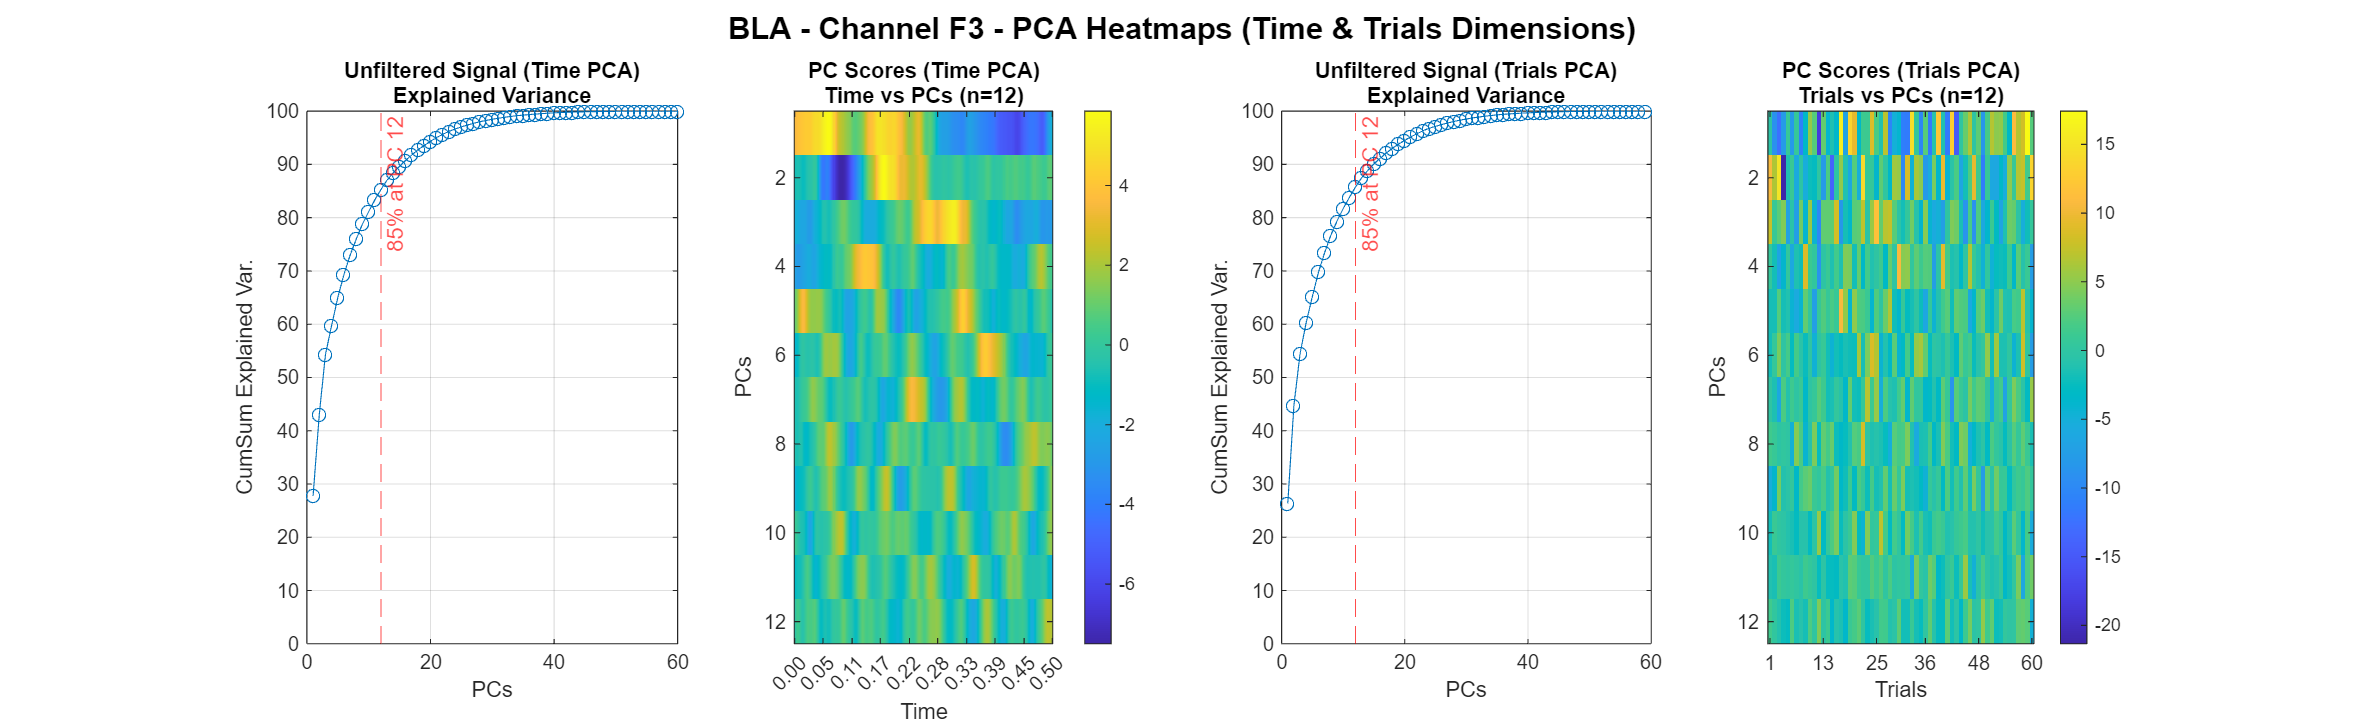

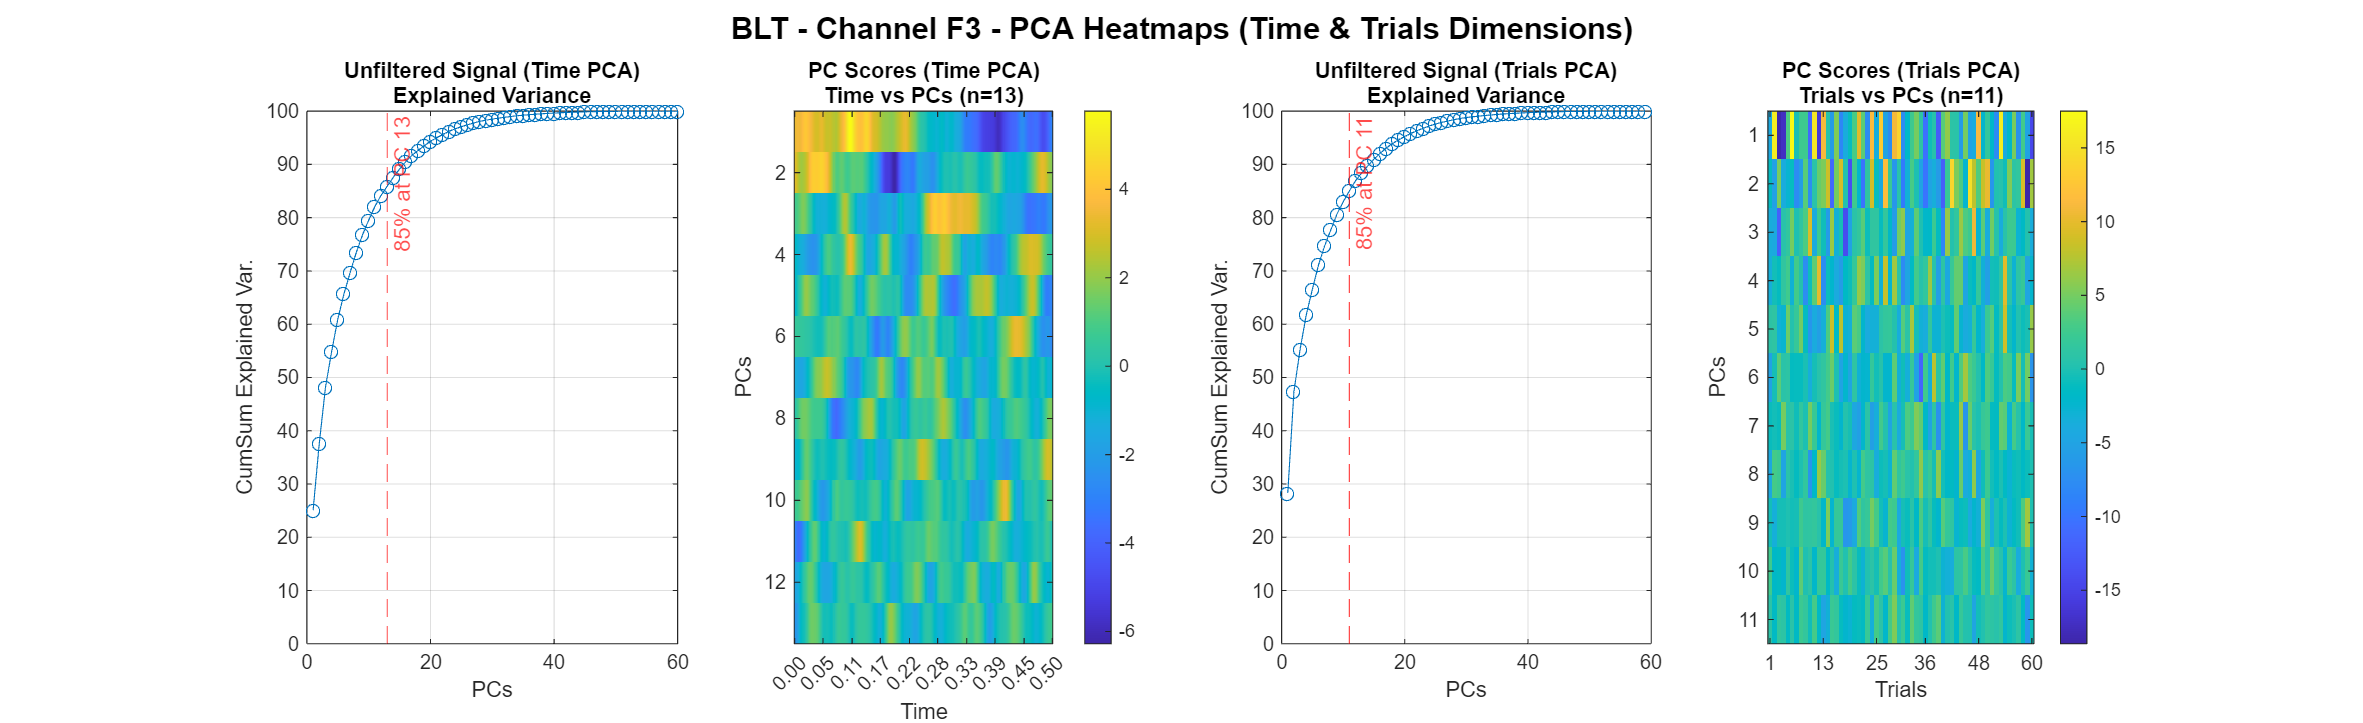

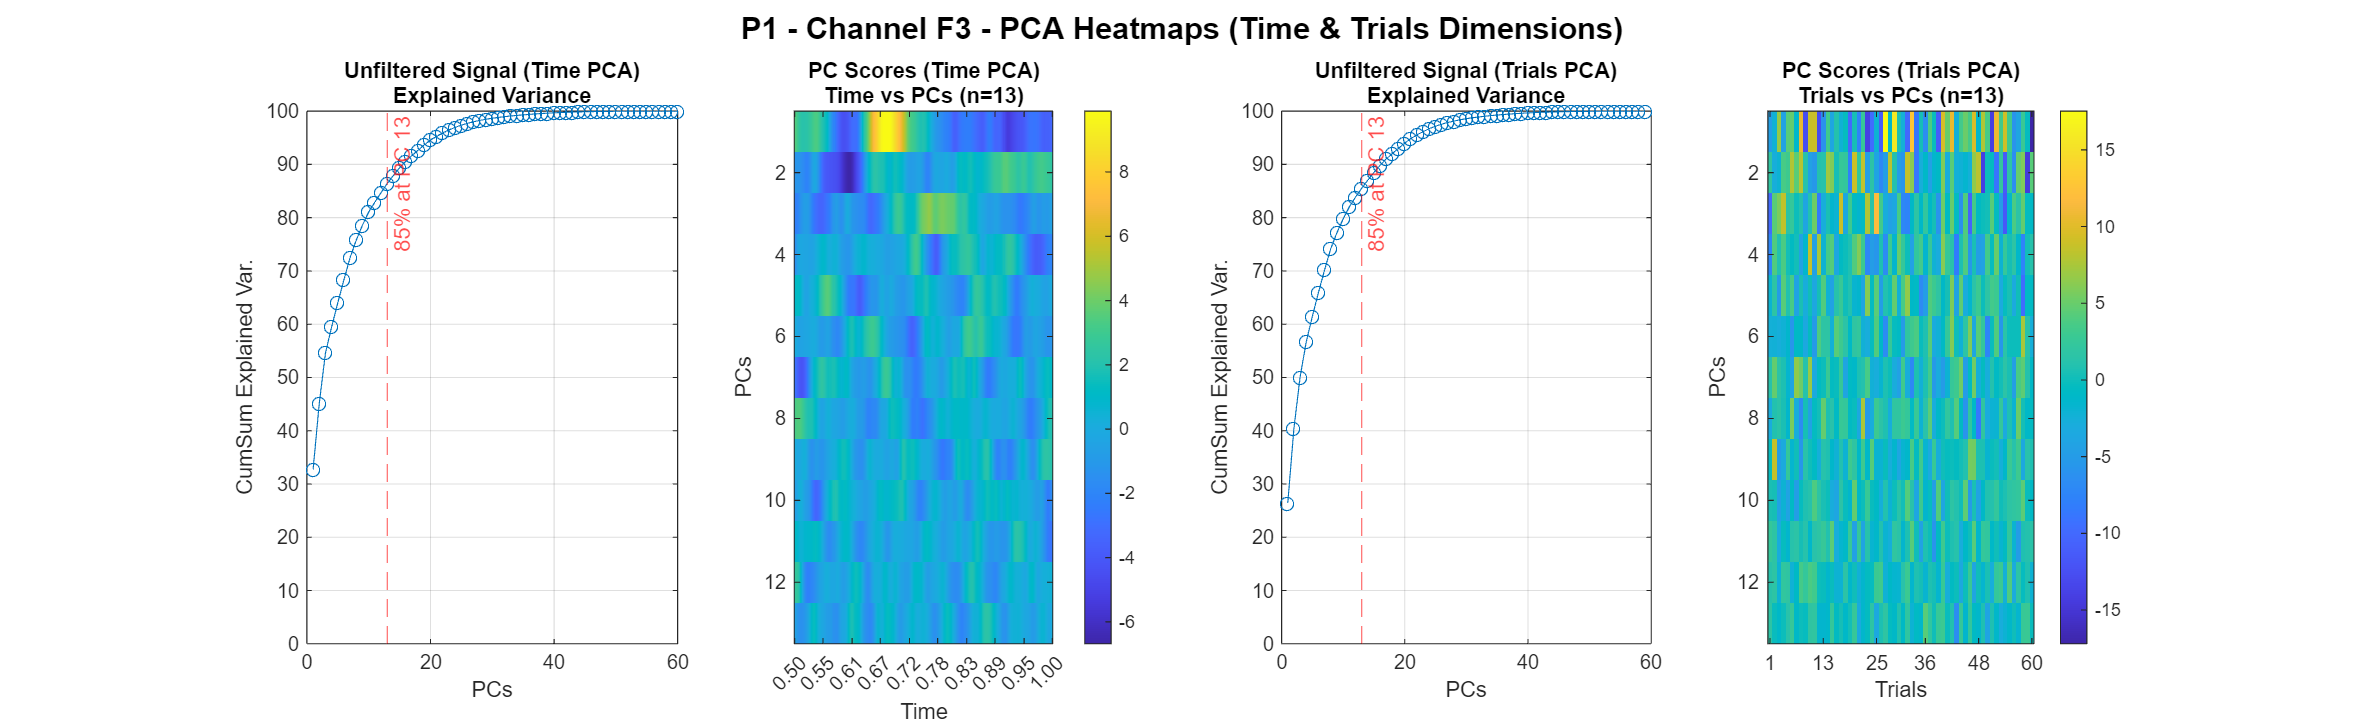

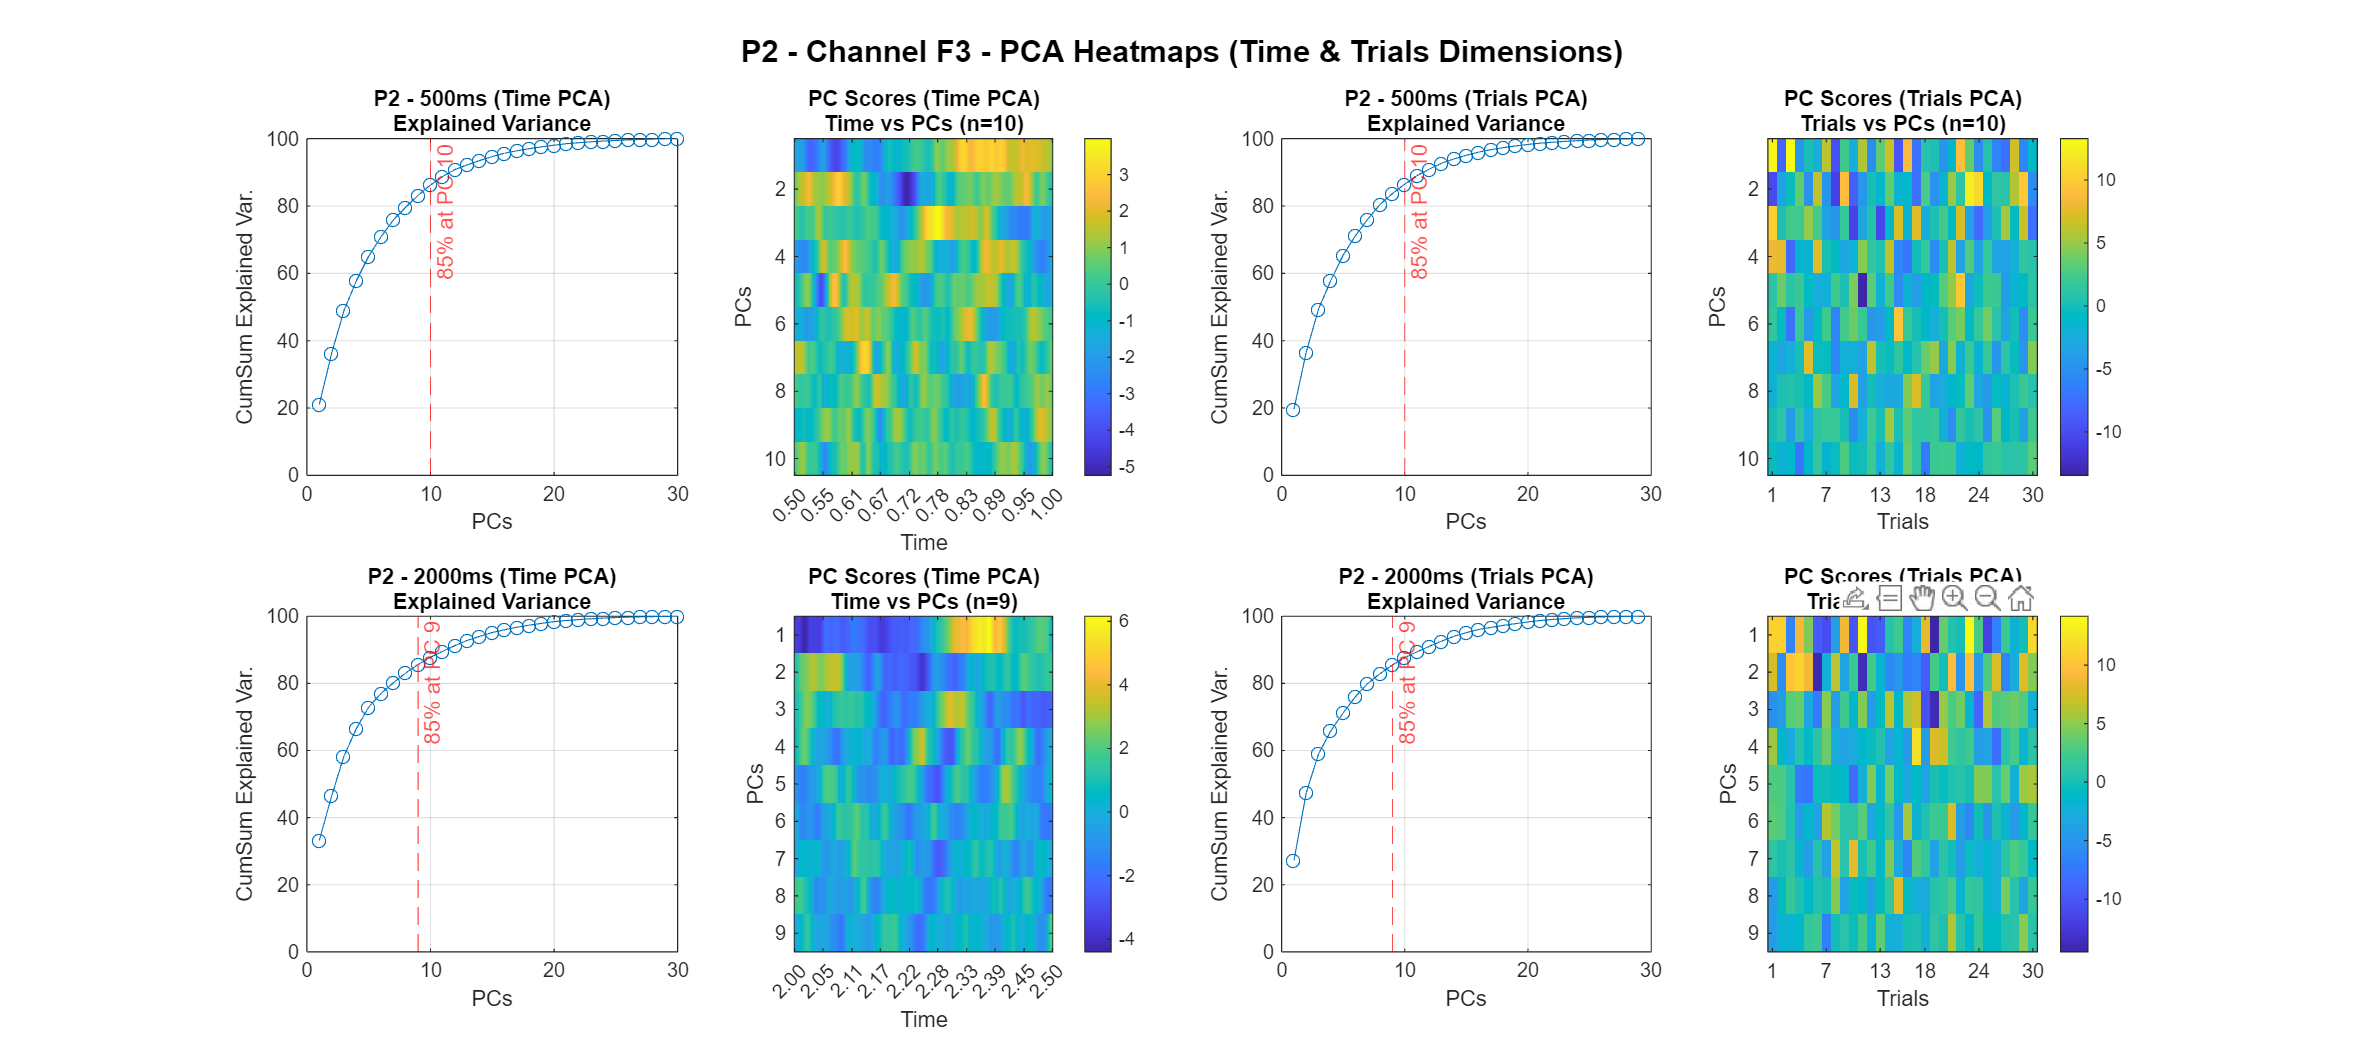

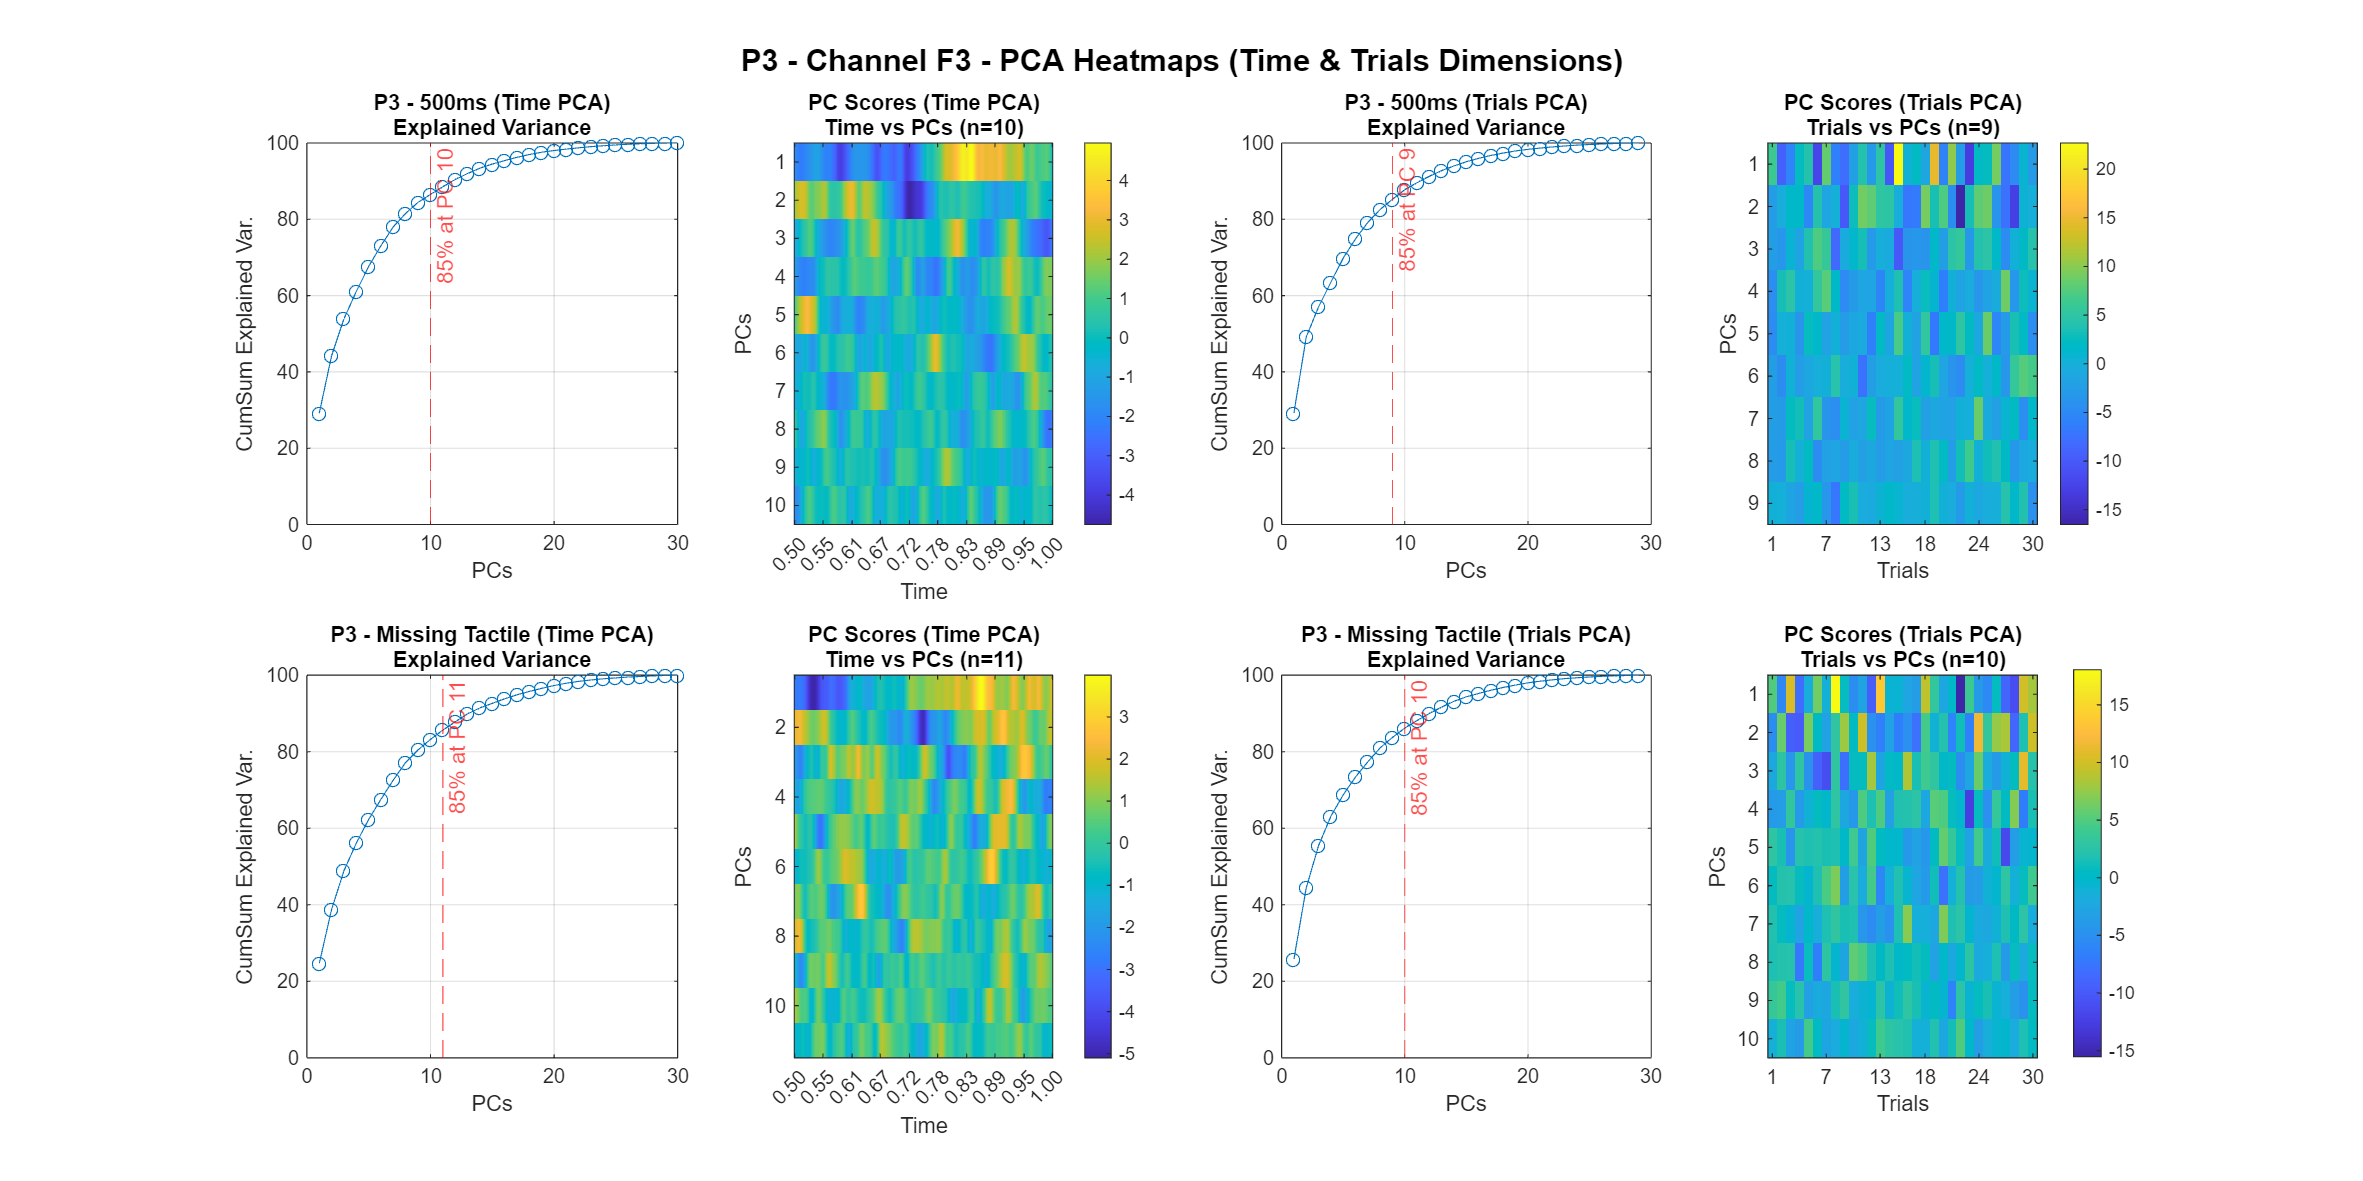

% For each channel and condition, create heatmaps of PCs explaining 85% variance
filter_types = {'unfiltered'}; % Currently, only 'unfiltered' is processed this way for plotting.
                               % If other filter types were processed and stored similarly in 'details', they could be added here.
filter_titles = {'Unfiltered Signal'};

for ch_idx = 1:length(channels)
    channel = channels{ch_idx};
    
    for cond_idx = 1:length(conditions)
        condition = conditions{cond_idx};
        
        % Check if we have any data for this condition and channel in all_results
        has_time_results = isfield(all_results.time, condition) && isfield(all_results.time.(condition), channel) && isfield(all_results.time.(condition).(channel), 'details');
        has_trials_results = isfield(all_results.trials, condition) && isfield(all_results.trials.(condition), channel) && isfield(all_results.trials.(condition).(channel), 'details');

        if ~has_time_results && ~has_trials_results
            warning('No PCA details found for condition %s, channel %s. Skipping plots.', condition, channel);
            continue;
        end
        
        if strcmp(condition, 'P2')
            figure_name = ['PCA Heatmaps - ' condition ' - Channel ' channel];
            figure('Name', figure_name, 'Position', [50, 50, 2000, 900]); 
            
            subconditions_p2 = {'p2_500', 'p2_2000'};
            subcondition_titles_p2 = {'P2 - 500ms', 'P2 - 2000ms'};
            
            for sub_plot_idx = 1:length(subconditions_p2)
                subcond_name = subconditions_p2{sub_plot_idx};
                subcond_title_str = [subcondition_titles_p2{sub_plot_idx}];

                % TIME DIMENSION PCA PLOTS for P2 subcondition
                subplot_prefix_time = (sub_plot_idx-1)*4;
                if has_time_results && isfield(all_results.time.(condition).(channel).details, subcond_name)
                    details_time_sub = all_results.time.(condition).(channel).details.(subcond_name);
                    if isfield(details_time_sub, 'explained') && ~isempty(details_time_sub.explained) && ...
                       isfield(details_time_sub, 'scores') && ~isempty(details_time_sub.scores)
                        
                        cum_explained_t = cumsum(details_time_sub.explained);
                        pcs_85_t = find(cum_explained_t >= 85, 1, 'first');
                        if isempty(pcs_85_t), pcs_85_t = length(details_time_sub.explained); end
                        
                        % Explained variance plot (Time Dim)
                        subplot(2, 4, subplot_prefix_time + 1);
                        plot(1:length(cum_explained_t), cum_explained_t, '-o');
                        title({[subcond_title_str ' (Time PCA)']; 'Explained Variance'});
                        xlabel('PCs'); ylabel('CumSum Explained Var.'); grid on; ylim([0 100]);
                        xline(pcs_85_t, '--r', ['85% at PC ' num2str(pcs_85_t)]);

                        % Heatmap (Time Dim)
                        subplot(2, 4, subplot_prefix_time + 2);
                        imagesc(details_time_sub.scores(:, 1:pcs_85_t)');
                        title({'PC Scores (Time PCA)'; ['Time vs PCs (n=' num2str(pcs_85_t) ')']});
                        xlabel('Time'); ylabel('PCs'); colorbar;
                        if isfield(details_time_sub, 'feature_labels') && ~isempty(details_time_sub.feature_labels)
                            time_pts = details_time_sub.feature_labels;
                            num_t_ticks = min(10, length(time_pts));
                            t_tick_idx = round(linspace(1, length(time_pts), num_t_ticks));
                            t_tick_lbl = arrayfun(@(x) sprintf('%.2f', x), time_pts(t_tick_idx), 'UniformOutput', false);
                            set(gca, 'XTick', t_tick_idx, 'XTickLabel', t_tick_lbl);
                        end
                    else
                        subplot(2,4, subplot_prefix_time + 1); title({subcond_title_str; 'No Time PCA data'}); axis off;
                        subplot(2,4, subplot_prefix_time + 2); title({subcond_title_str; 'No Time PCA Scores'}); axis off;
                    end
                else
                    subplot(2,4, subplot_prefix_time + 1); title({subcond_title_str; 'No Time PCA details'}); axis off;
                    subplot(2,4, subplot_prefix_time + 2); title({subcond_title_str; 'No Time PCA details'}); axis off;
                end

                % TRIALS DIMENSION PCA PLOTS for P2 subcondition
                if has_trials_results && isfield(all_results.trials.(condition).(channel).details, subcond_name)
                    details_trials_sub = all_results.trials.(condition).(channel).details.(subcond_name);
                     if isfield(details_trials_sub, 'explained') && ~isempty(details_trials_sub.explained) && ...
                        isfield(details_trials_sub, 'scores') && ~isempty(details_trials_sub.scores)

                        cum_explained_tr = cumsum(details_trials_sub.explained);
                        pcs_85_tr = find(cum_explained_tr >= 85, 1, 'first');
                        if isempty(pcs_85_tr), pcs_85_tr = length(details_trials_sub.explained); end

                        % Explained variance plot (Trials Dim)
                        subplot(2, 4, subplot_prefix_time + 3);
                        plot(1:length(cum_explained_tr), cum_explained_tr, '-o');
                        title({[subcond_title_str ' (Trials PCA)']; 'Explained Variance'});
                        xlabel('PCs'); ylabel('CumSum Explained Var.'); grid on; ylim([0 100]);
                        xline(pcs_85_tr, '--r', ['85% at PC ' num2str(pcs_85_tr)]);
                        
                        % Heatmap (Trials Dim)
                        subplot(2, 4, subplot_prefix_time + 4);
                        imagesc(details_trials_sub.scores(:, 1:pcs_85_tr)');
                        title({'PC Scores (Trials PCA)'; ['Trials vs PCs (n=' num2str(pcs_85_tr) ')']});
                        xlabel('Trials'); ylabel('PCs'); colorbar;
                        if isfield(details_trials_sub, 'num_observations') && details_trials_sub.num_observations > 0
                            num_tr_obs = details_trials_sub.num_observations;
                            num_tr_ticks = min(6, num_tr_obs);
                            tr_tick_idx = round(linspace(1, num_tr_obs, num_tr_ticks));                
                            set(gca, 'XTick', tr_tick_idx);
                        end
                    else
                        subplot(2,4, subplot_prefix_time + 3); title({subcond_title_str; 'No Trial PCA data'}); axis off;
                        subplot(2,4, subplot_prefix_time + 4); title({subcond_title_str; 'No Trial PCA Scores'}); axis off;
                    end
                else
                    subplot(2,4, subplot_prefix_time + 3); title({subcond_title_str; 'No Trial PCA details'}); axis off;
                    subplot(2,4, subplot_prefix_time + 4); title({subcond_title_str; 'No Trial PCA details'}); axis off;
                end
            end
            sgtitle([condition ' - Channel ' channel ' - PCA Heatmaps (Time & Trials Dimensions)'], 'FontSize', 14, 'FontWeight', 'bold');
            saveas(gcf, fullfile(output_path_perChannel, ['PCA_Heatmaps_TimeTrials_' condition '_Channel_' channel '.fig']));
            saveas(gcf, fullfile(output_path_perChannel, ['PCA_Heatmaps_TimeTrials_' condition '_Channel_' channel '.png']));
            
        elseif strcmp(condition, 'P3')
            figure_name = ['PCA Heatmaps - ' condition ' - Channel ' channel];
            figure('Name', figure_name, 'Position', [50, 50, 1800, 900]);
            
            subconditions_p3 = {'p3_500', 'p3_missing'};
            subcondition_titles_p3 = {'P3 - 500ms', 'P3 - Missing Tactile'};

            for sub_plot_idx = 1:length(subconditions_p3)
                subcond_name = subconditions_p3{sub_plot_idx};
                subcond_title_str = [subcondition_titles_p3{sub_plot_idx}];
                subplot_prefix_time = (sub_plot_idx-1)*4;

                % TIME DIMENSION PCA PLOTS for P3 subcondition
                if has_time_results && isfield(all_results.time.(condition).(channel).details, subcond_name)
                    details_time_sub = all_results.time.(condition).(channel).details.(subcond_name);
                    if isfield(details_time_sub, 'explained') && ~isempty(details_time_sub.explained) && ...
                       isfield(details_time_sub, 'scores') && ~isempty(details_time_sub.scores)
                        cum_explained_t = cumsum(details_time_sub.explained);
                        pcs_85_t = find(cum_explained_t >= 85, 1, 'first');
                        if isempty(pcs_85_t), pcs_85_t = length(details_time_sub.explained); end
                        
                        subplot(2, 4, subplot_prefix_time + 1);
                        plot(1:length(cum_explained_t), cum_explained_t, '-o');
                        title({[subcond_title_str ' (Time PCA)']; 'Explained Variance'});
                        xlabel('PCs'); ylabel('CumSum Explained Var.'); grid on; ylim([0 100]);
                        xline(pcs_85_t, '--r', ['85% at PC ' num2str(pcs_85_t)]);

                        subplot(2, 4, subplot_prefix_time + 2);
                        imagesc(details_time_sub.scores(:, 1:pcs_85_t)');
                        title({'PC Scores (Time PCA)'; ['Time vs PCs (n=' num2str(pcs_85_t) ')']});
                        xlabel('Time'); ylabel('PCs'); colorbar;
                        if isfield(details_time_sub, 'feature_labels') && ~isempty(details_time_sub.feature_labels)
                            time_pts = details_time_sub.feature_labels;
                            num_t_ticks = min(10, length(time_pts));
                            t_tick_idx = round(linspace(1, length(time_pts), num_t_ticks));
                            t_tick_lbl = arrayfun(@(x) sprintf('%.2f', x), time_pts(t_tick_idx), 'UniformOutput', false);
                            set(gca, 'XTick', t_tick_idx, 'XTickLabel', t_tick_lbl);
                        end
                    else
                        subplot(2,4, subplot_prefix_time + 1); title({subcond_title_str; 'No Time PCA data'}); axis off;
                        subplot(2,4, subplot_prefix_time + 2); title({subcond_title_str; 'No Time PCA Scores'}); axis off;
                    end
                else
                    subplot(2,4, subplot_prefix_time + 1); title({subcond_title_str; 'No Time PCA details'}); axis off;
                    subplot(2,4, subplot_prefix_time + 2); title({subcond_title_str; 'No Time PCA details'}); axis off;
                end
                
                % TRIALS DIMENSION PCA PLOTS for P3 subcondition
                if has_trials_results && isfield(all_results.trials.(condition).(channel).details, subcond_name)
                    details_trials_sub = all_results.trials.(condition).(channel).details.(subcond_name);
                     if isfield(details_trials_sub, 'explained') && ~isempty(details_trials_sub.explained) && ...
                        isfield(details_trials_sub, 'scores') && ~isempty(details_trials_sub.scores)
                        cum_explained_tr = cumsum(details_trials_sub.explained);
                        pcs_85_tr = find(cum_explained_tr >= 85, 1, 'first');
                        if isempty(pcs_85_tr), pcs_85_tr = length(details_trials_sub.explained); end

                        subplot(2, 4, subplot_prefix_time + 3);
                        plot(1:length(cum_explained_tr), cum_explained_tr, '-o');
                        title({[subcond_title_str ' (Trials PCA)']; 'Explained Variance'});
                        xlabel('PCs'); ylabel('CumSum Explained Var.'); grid on; ylim([0 100]);
                        xline(pcs_85_tr, '--r', ['85% at PC ' num2str(pcs_85_tr)]);
                        
                        subplot(2, 4, subplot_prefix_time + 4);
                        imagesc(details_trials_sub.scores(:, 1:pcs_85_tr)');
                        title({'PC Scores (Trials PCA)'; ['Trials vs PCs (n=' num2str(pcs_85_tr) ')']});
                        xlabel('Trials'); ylabel('PCs'); colorbar;
                        if isfield(details_trials_sub, 'num_observations') && details_trials_sub.num_observations > 0
                            num_tr_obs = details_trials_sub.num_observations;
                            num_tr_ticks = min(6, num_tr_obs);
                            tr_tick_idx = round(linspace(1, num_tr_obs, num_tr_ticks));                
                            set(gca, 'XTick', tr_tick_idx);
                        end
                    else
                        subplot(2,4, subplot_prefix_time + 3); title({subcond_title_str; 'No Trial PCA data'}); axis off;
                        subplot(2,4, subplot_prefix_time + 4); title({subcond_title_str; 'No Trial PCA Scores'}); axis off;
                    end
                else
                    subplot(2,4, subplot_prefix_time + 3); title({subcond_title_str; 'No Trial PCA details'}); axis off;
                    subplot(2,4, subplot_prefix_time + 4); title({subcond_title_str; 'No Trial PCA details'}); axis off;
                end
            end
            sgtitle([condition ' - Channel ' channel ' - PCA Heatmaps (Time & Trials Dimensions)'], 'FontSize', 14, 'FontWeight', 'bold');
            saveas(gcf, fullfile(output_path_perChannel, ['PCA_Heatmaps_TimeTrials_' condition '_Channel_' channel '.fig']));
            saveas(gcf, fullfile(output_path_perChannel, ['PCA_Heatmaps_TimeTrials_' condition '_Channel_' channel '.png']));
            
        else % For BLA, BLT, P1 conditions
            figure_name = ['PCA Heatmaps - ' condition ' - Channel ' channel];
            figure('Name', figure_name, 'Position', [50, 50, 1800, 550 * length(filter_types)]);
            
            for f_plot_idx = 1:length(filter_types)
                filter_type_name = filter_types{f_plot_idx};
                filter_title_str = [filter_titles{f_plot_idx}];
                subplot_prefix_filt = (f_plot_idx-1)*4;

                % TIME DIMENSION PCA PLOTS for filter_type
                if has_time_results && isfield(all_results.time.(condition).(channel).details, filter_type_name)
                    details_time_filt = all_results.time.(condition).(channel).details.(filter_type_name);
                    if isfield(details_time_filt, 'explained') && ~isempty(details_time_filt.explained) && ...
                       isfield(details_time_filt, 'scores') && ~isempty(details_time_filt.scores)
                        cum_explained_t = cumsum(details_time_filt.explained);
                        pcs_85_t = find(cum_explained_t >= 85, 1, 'first');
                        if isempty(pcs_85_t), pcs_85_t = length(details_time_filt.explained); end

                        subplot(length(filter_types), 4, subplot_prefix_filt + 1);
                        plot(1:length(cum_explained_t), cum_explained_t, '-o');
                        title({[filter_title_str ' (Time PCA)']; 'Explained Variance'});
                        xlabel('PCs'); ylabel('CumSum Explained Var.'); grid on; ylim([0 100]);
                        xline(pcs_85_t, '--r', ['85% at PC ' num2str(pcs_85_t)]);

                        subplot(length(filter_types), 4, subplot_prefix_filt + 2);
                        imagesc(details_time_filt.scores(:, 1:pcs_85_t)');
                        title({'PC Scores (Time PCA)'; ['Time vs PCs (n=' num2str(pcs_85_t) ')']});
                        xlabel('Time'); ylabel('PCs'); colorbar;
                        if isfield(details_time_filt, 'feature_labels') && ~isempty(details_time_filt.feature_labels)
                            time_pts = details_time_filt.feature_labels;
                            num_t_ticks = min(10, length(time_pts));
                            t_tick_idx = round(linspace(1, length(time_pts), num_t_ticks));
                            t_tick_lbl = arrayfun(@(x) sprintf('%.2f', x), time_pts(t_tick_idx), 'UniformOutput', false);
                            set(gca, 'XTick', t_tick_idx, 'XTickLabel', t_tick_lbl);
                        end
                    else
                        subplot(length(filter_types),4, subplot_prefix_filt + 1); title({filter_title_str; 'No Time PCA data'}); axis off;
                        subplot(length(filter_types),4, subplot_prefix_filt + 2); title({filter_title_str; 'No Time PCA Scores'}); axis off;
                    end
                else
                    subplot(length(filter_types),4, subplot_prefix_filt + 1); title({filter_title_str; 'No Time PCA details'}); axis off;
                    subplot(length(filter_types),4, subplot_prefix_filt + 2); title({filter_title_str; 'No Time PCA details'}); axis off;
                end

                % TRIALS DIMENSION PCA PLOTS for filter_type
                if has_trials_results && isfield(all_results.trials.(condition).(channel).details, filter_type_name)
                    details_trials_filt = all_results.trials.(condition).(channel).details.(filter_type_name);
                     if isfield(details_trials_filt, 'explained') && ~isempty(details_trials_filt.explained) && ...
                        isfield(details_trials_filt, 'scores') && ~isempty(details_trials_filt.scores)
                        cum_explained_tr = cumsum(details_trials_filt.explained);
                        pcs_85_tr = find(cum_explained_tr >= 85, 1, 'first');
                        if isempty(pcs_85_tr), pcs_85_tr = length(details_trials_filt.explained); end

                        subplot(length(filter_types), 4, subplot_prefix_filt + 3);
                        plot(1:length(cum_explained_tr), cum_explained_tr, '-o');
                        title({[filter_title_str ' (Trials PCA)']; 'Explained Variance'});
                        xlabel('PCs'); ylabel('CumSum Explained Var.'); grid on; ylim([0 100]);
                        xline(pcs_85_tr, '--r', ['85% at PC ' num2str(pcs_85_tr)]);
                        
                        subplot(length(filter_types), 4, subplot_prefix_filt + 4);
                        imagesc(details_trials_filt.scores(:, 1:pcs_85_tr)');
                        title({'PC Scores (Trials PCA)'; ['Trials vs PCs (n=' num2str(pcs_85_tr) ')']});
                        xlabel('Trials'); ylabel('PCs'); colorbar;
                        if isfield(details_trials_filt, 'num_observations') && details_trials_filt.num_observations > 0
                            num_tr_obs = details_trials_filt.num_observations;
                            num_tr_ticks = min(6, num_tr_obs);
                            tr_tick_idx = round(linspace(1, num_tr_obs, num_tr_ticks));                
                            set(gca, 'XTick', tr_tick_idx);
                        end
                    else
                        subplot(length(filter_types),4, subplot_prefix_filt + 3); title({filter_title_str; 'No Trial PCA data'}); axis off;
                        subplot(length(filter_types),4, subplot_prefix_filt + 4); title({filter_title_str; 'No Trial PCA Scores'}); axis off;
                    end
                else
                    subplot(length(filter_types),4, subplot_prefix_filt + 3); title({filter_title_str; 'No Trial PCA details'}); axis off;
                    subplot(length(filter_types),4, subplot_prefix_filt + 4); title({filter_title_str; 'No Trial PCA details'}); axis off;
                end
            end
            sgtitle([condition ' - Channel ' channel ' - PCA Heatmaps (Time & Trials Dimensions)'], 'FontSize', 14, 'FontWeight', 'bold');
            saveas(gcf, fullfile(output_path_perChannel, ['PCA_Heatmaps_TimeTrials_' condition '_Channel_' channel '.fig']));
            saveas(gcf, fullfile(output_path_perChannel, ['PCA_Heatmaps_TimeTrials_' condition '_Channel_' channel '.png']));
        end
        
        % Consider closing figures if many are generated to save memory:
        % close(gcf); 
    end % End condition loop for plotting
end % End channel loop for plotting


fprintf('Heatmap visualization complete! Results saved to: %s\n', output_path_perChannel);

Heatmap visualization complete! Results saved to: C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\pca_per_channel


fprintf('Analysis complete! Results saved to: %s\n', output_path_perChannel);

Analysis complete! Results saved to: C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\pca_per_channel


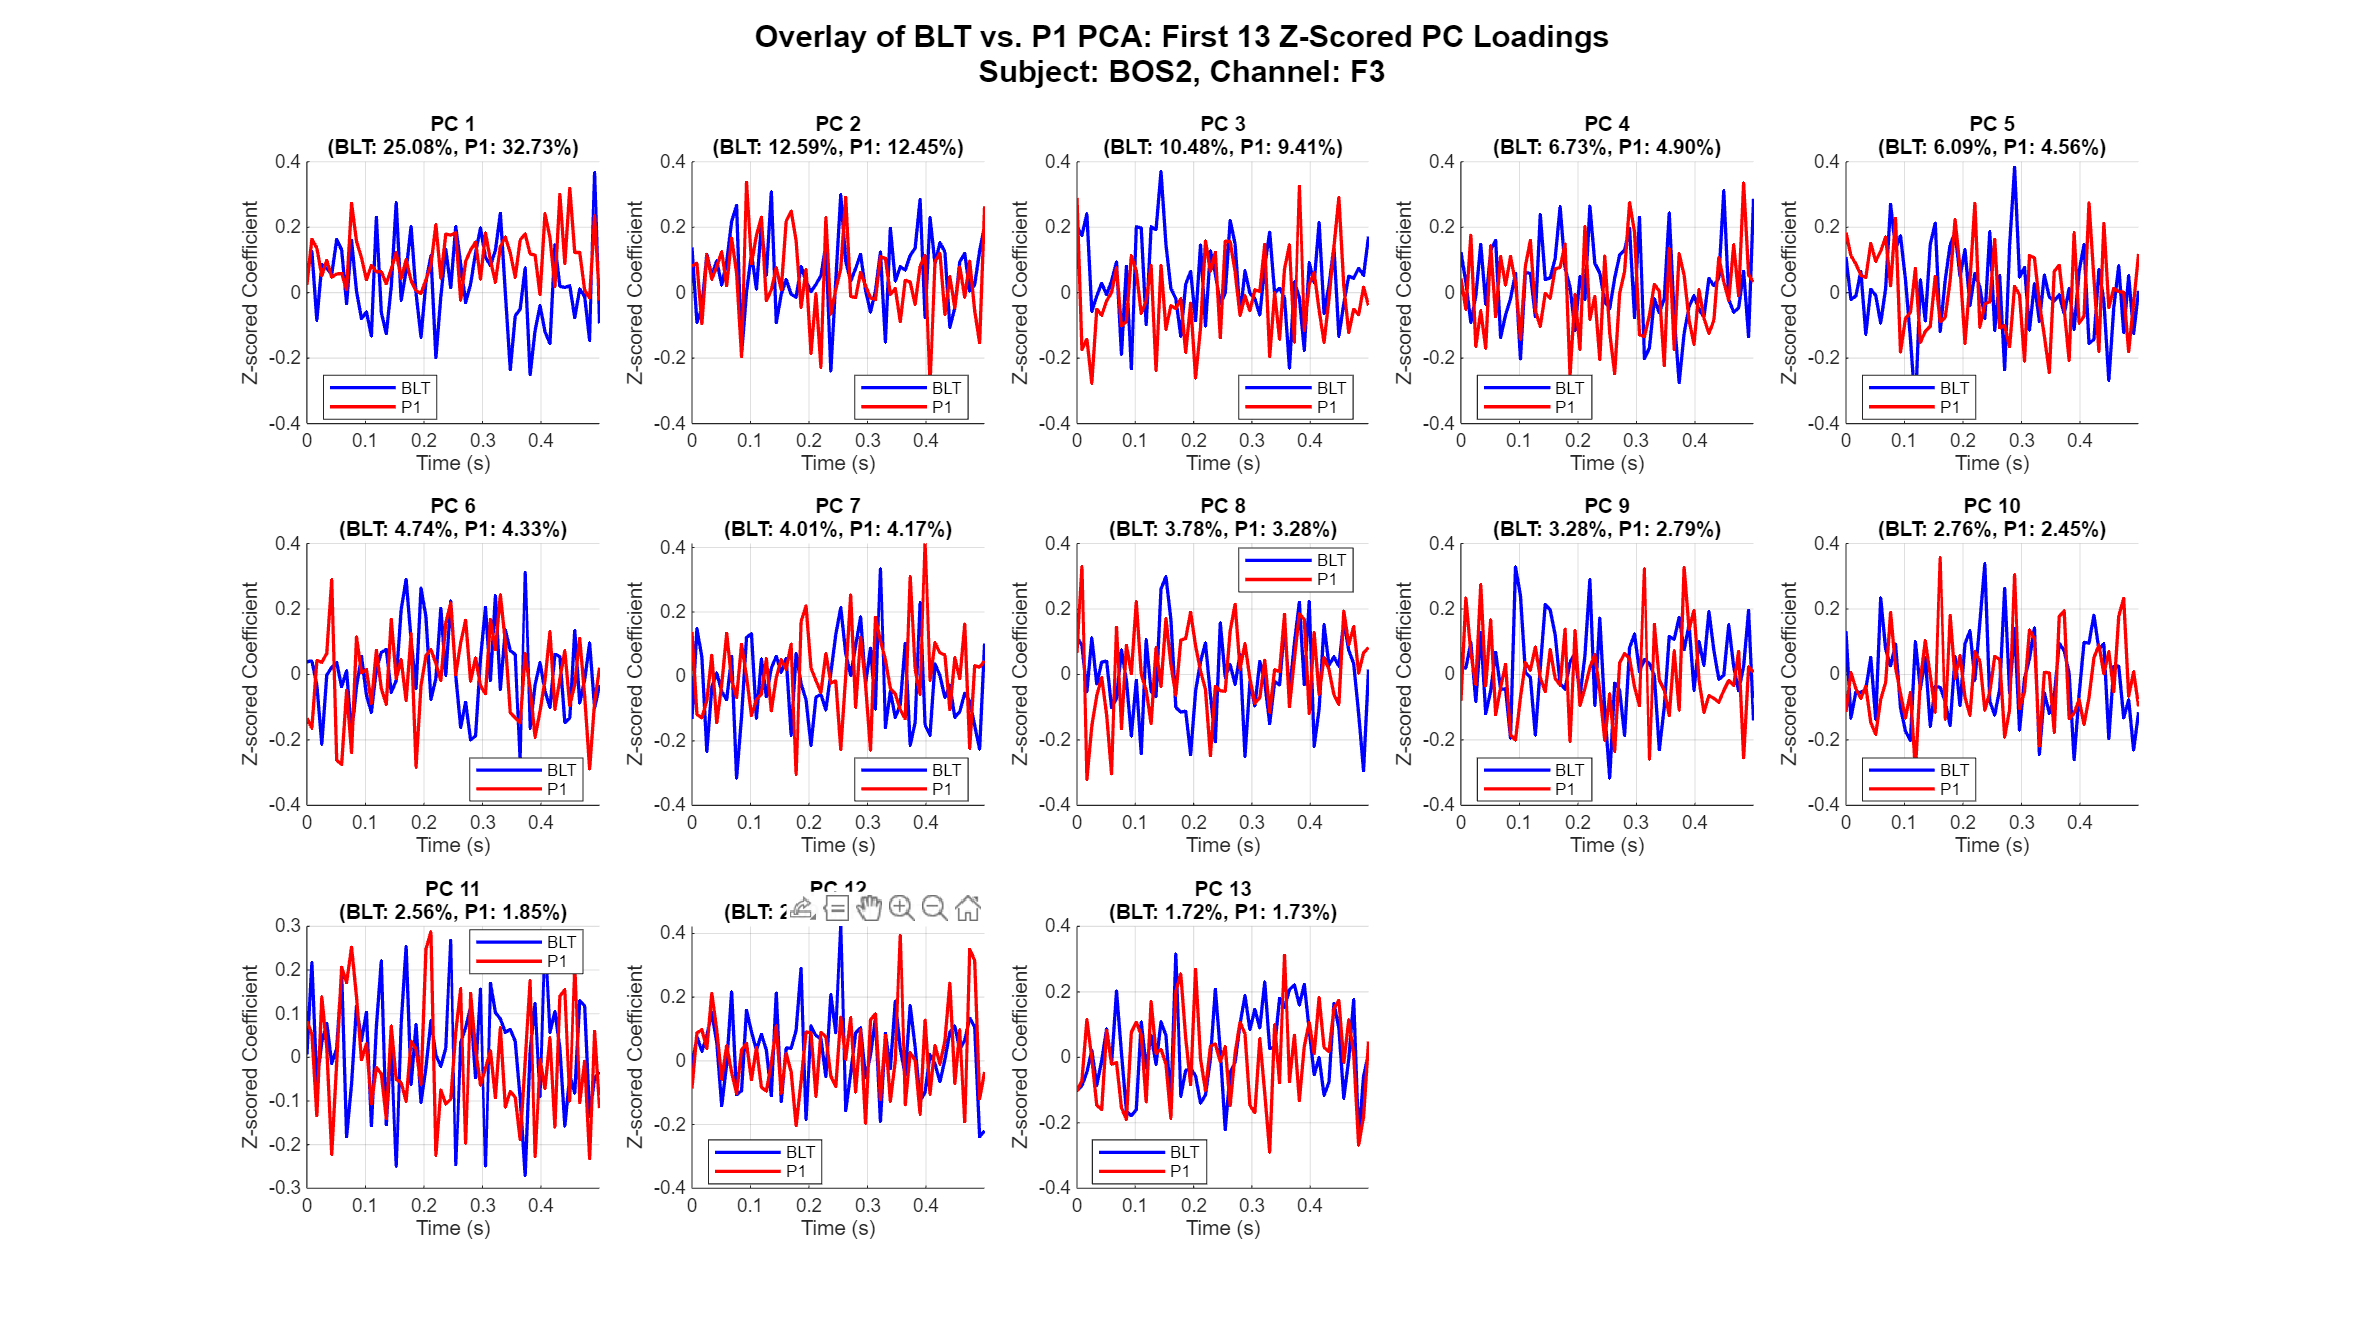

% Line plots for PC's greater than 85% cumulative explained variance
% BLT vs. P1
% Loop over subjects
for subj_idx = 1:length(subjects)
    subject = subjects{subj_idx};
     % Process each channel
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        
        blt_details = all_results.time.BLT.(channel).details.unfiltered;
        blt_cum_explained = cumsum(blt_details.explained);
        blt_pcs_85 = find(blt_cum_explained >= 85, 1, 'first');
        p1_details = all_results.time.P1.(channel).details.unfiltered;
        p1_cum_explained = cumsum(p1_details.explained);
        p1_pcs_85 = find(p1_cum_explained >= 85, 1, 'first');

        time_points_blt = linspace(0,0.5,60);
        time_points_p1 = time_points_blt;
        coeff_blt = blt_details.coeff;
        coeff_p1 = p1_details.coeff;

        if blt_pcs_85 > p1_pcs_85
            num_pcs_to_overlay = blt_pcs_85;
        else
            num_pcs_to_overlay = p1_pcs_85;
        end

        
        figure('Name', ['Overlay Line Plots of First ' num2str(num_pcs_to_overlay) ' PCs - ' subject ' - Ch ' channel], ...
               'Position', [50, 50, 1600, 900]); % Adjusted size for better visibility
        
        % Determine subplot layout (e.g., 2 rows, 5 columns for up to 10 PCs)
        if num_pcs_to_overlay <= 5
            n_rows = 1;
            n_cols = num_pcs_to_overlay;
        elseif num_pcs_to_overlay <=10 % num_pcs_to_overlay is between 6 and 10
            n_rows = 2;
            n_cols = ceil(num_pcs_to_overlay / n_rows); 
        else
            n_rows = 3;
            n_cols = ceil(num_pcs_to_overlay / n_rows); 
        end

        for pc_idx = 1:num_pcs_to_overlay
            subplot(n_rows, n_cols, pc_idx);
            hold on; % Hold on to plot both lines in the same subplot

            % Plot BLT PC
            plot(time_points_blt, coeff_blt(:, pc_idx), 'b-', 'LineWidth', 1.5, 'DisplayName', 'BLT');
            
            % Plot P1 PC
            plot(time_points_p1, coeff_p1(:, pc_idx), 'r-', 'LineWidth', 1.5, 'DisplayName', 'P1');
            
            hold off;
            
            % Add title with explained variance for both
            title_str = {['PC ' num2str(pc_idx)], ...
                         ['(BLT: ' sprintf('%.2f', blt_details.explained(pc_idx)) '%, ', ...
                          'P1: ' sprintf('%.2f', p1_details.explained(pc_idx)) '%)']};
            title(title_str);
            
            xlabel('Time (s)');
            ylabel('Z-scored Coefficient');
            xlim([0 0.5]);
            grid on;
          
            legend('show', 'Location', 'best');

        end
        
        sgtitle(['Overlay of BLT vs. P1 PCA: First ' num2str(num_pcs_to_overlay) ' Z-Scored PC Loadings' ...
            newline 'Subject: ' subject ', Channel: ' channel], 'FontSize', 14, 'FontWeight', 'bold');
        
        overlay_fig_filename = fullfile(output_path_perChannel, ['Overlay_PCA_LinePlots_TopPCs_' subject '_' channel]);
        saveas(gcf, [overlay_fig_filename '.fig']);
        saveas(gcf, [overlay_fig_filename '.png']);
        
    end
end

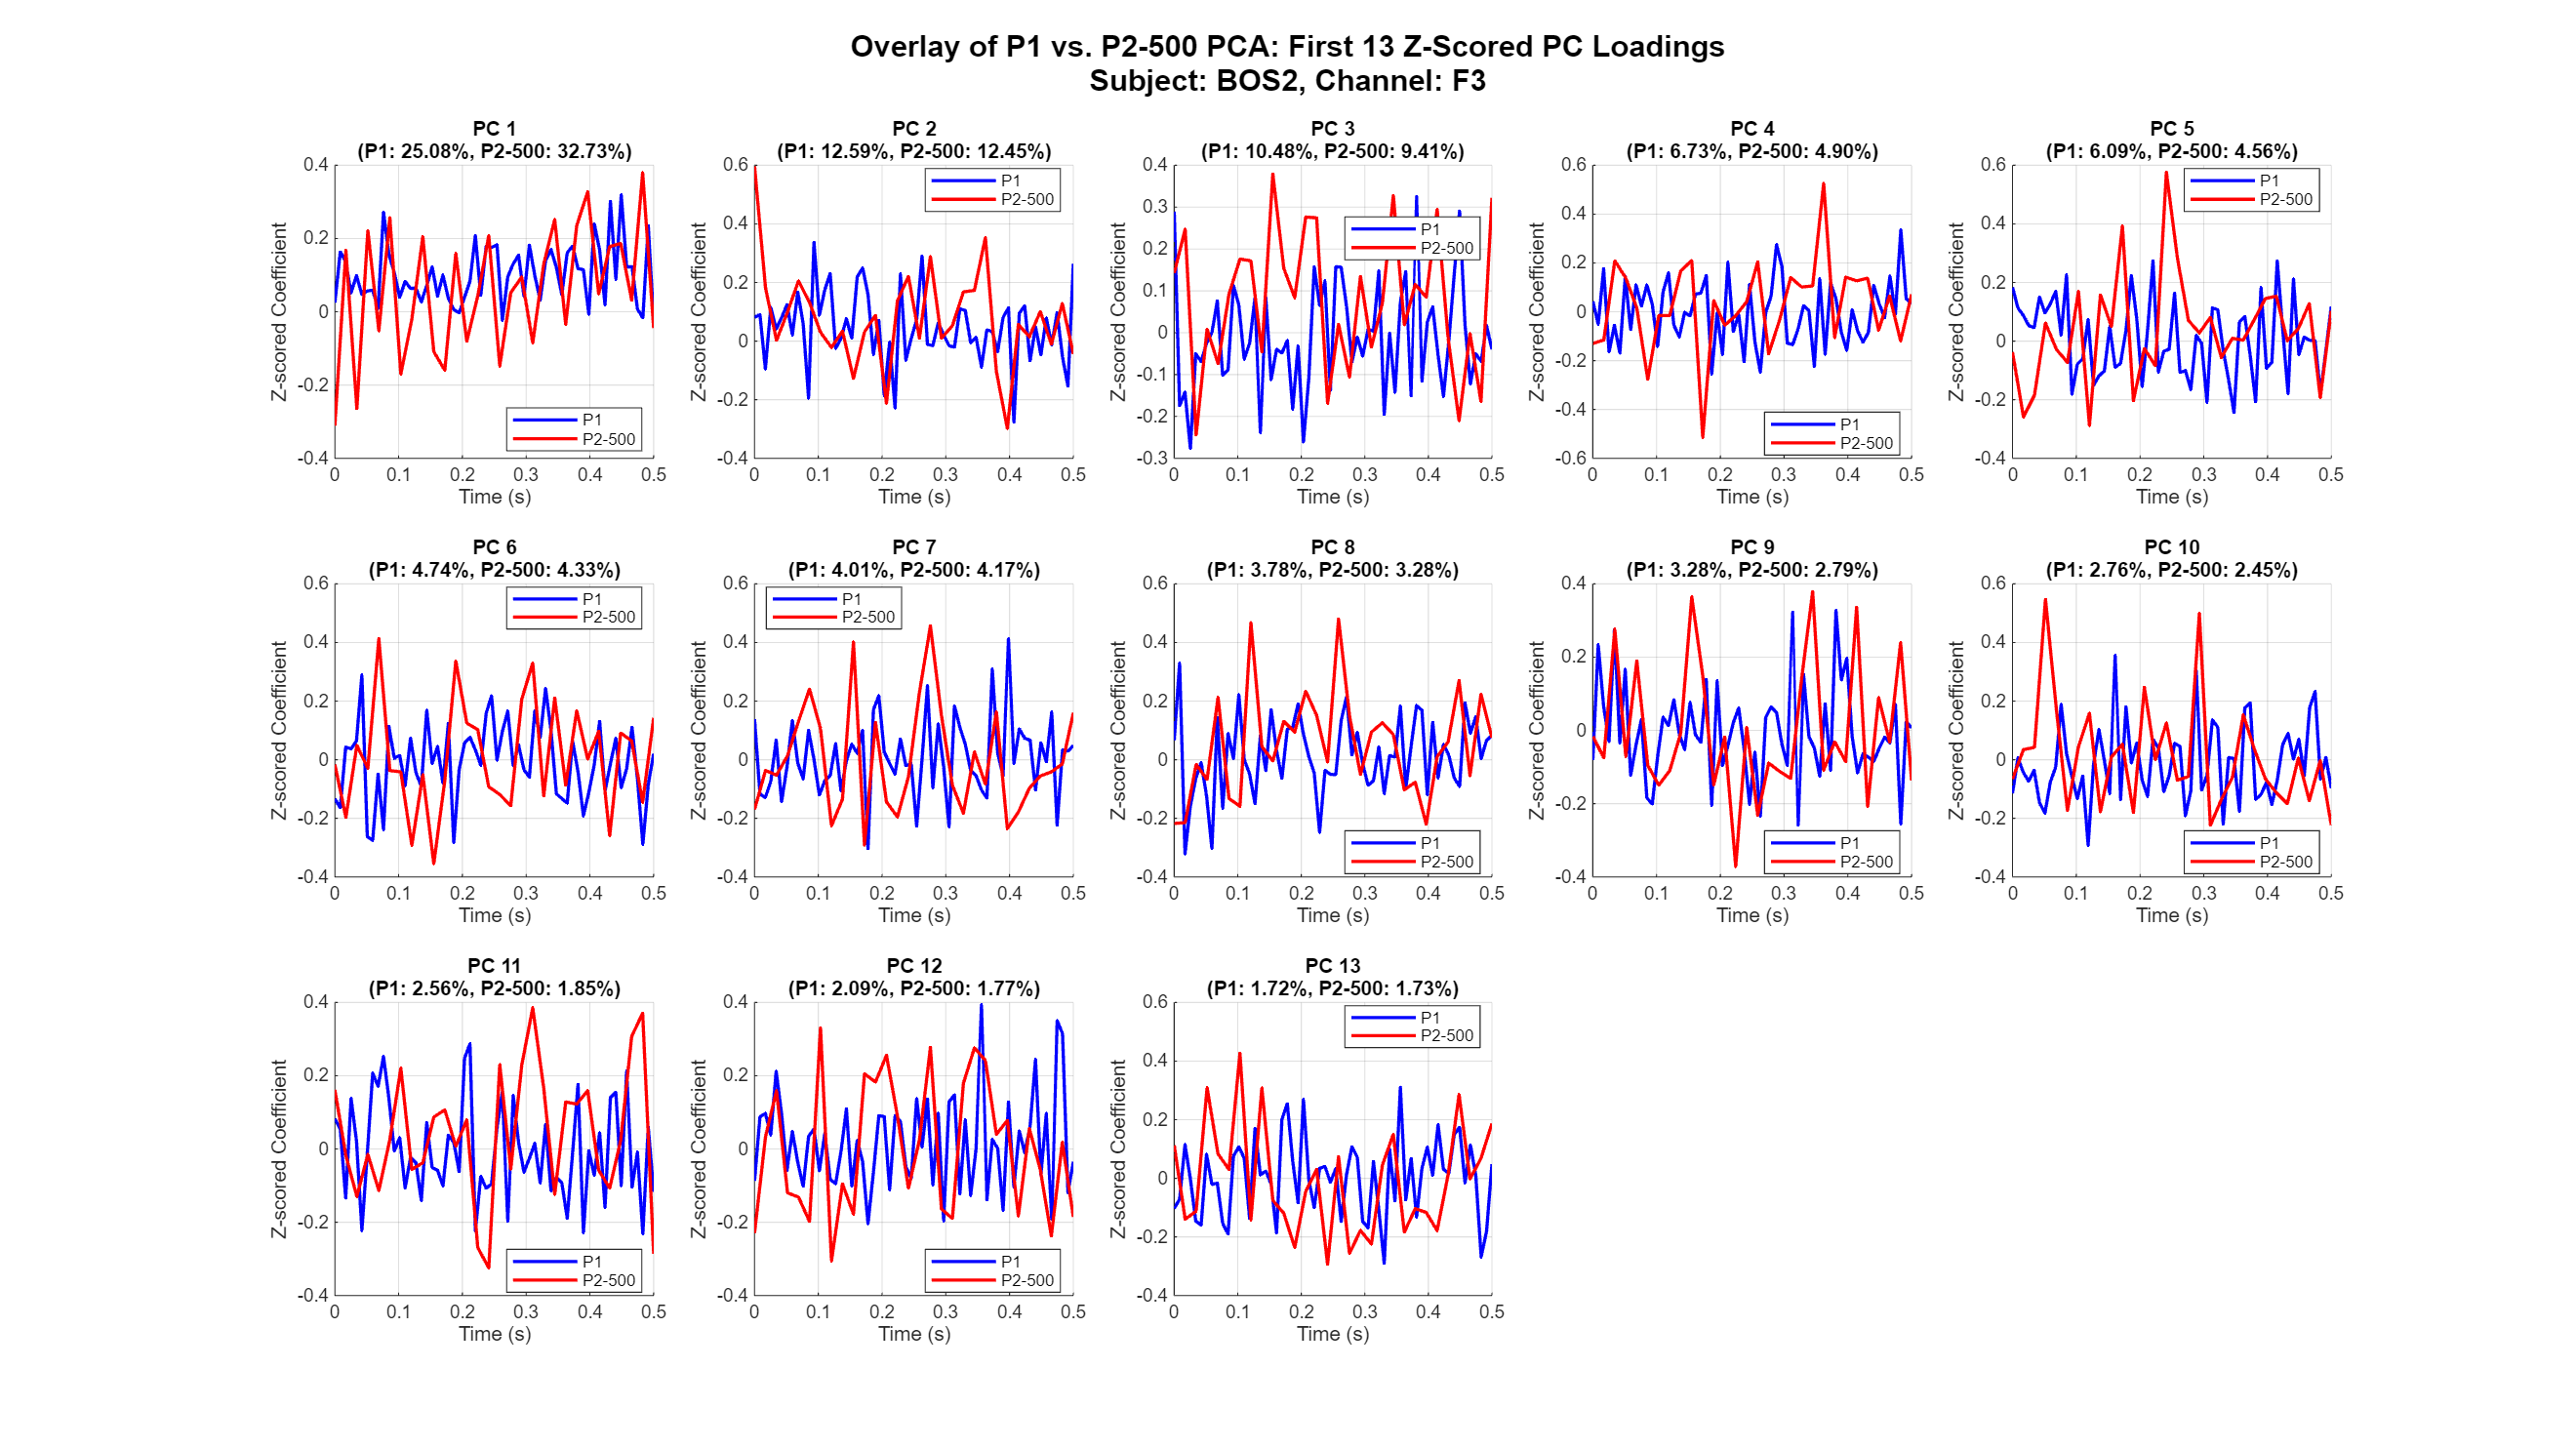

% Line plots for PC's greater than 85% cumulative explained variance

% P1 vs. P2A (P2-500)
% P2A vs. P2B
% P2A vs. P2X (from 1 sec to 1.5 sec)

% Loop over subjects
for subj_idx = 1:length(subjects)
    subject = subjects{subj_idx};
     % Process each channel
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        
        p2a_details = all_results.time.P2.(channel).details.p2_500;
        p2a_cum_explained = cumsum(p2a_details.explained);
        p2a_pcs_85 = find(p2a_cum_explained >= 85, 1, 'first');
        p1_details = all_results.time.P1.(channel).details.unfiltered;
        p1_cum_explained = cumsum(p1_details.explained);
        p1_pcs_85 = find(p1_cum_explained >= 85, 1, 'first');

        time_points_p2a = linspace(0,0.5,30);
        time_points_p1 = linspace(0,0.5,60);
        coeff_p2a = p2a_details.coeff;
        coeff_p1 = p1_details.coeff;

        if p2a_pcs_85 > p1_pcs_85
            num_pcs_to_overlay = p2a_pcs_85;
        else
            num_pcs_to_overlay = p1_pcs_85;
        end

        
        figure('Name', ['Overlay Line Plots of First ' num2str(num_pcs_to_overlay) ' PCs - ' subject ' - Ch ' channel], ...
               'Position', [50, 50, 1600, 900]); % Adjusted size for better visibility
        
        % Determine subplot layout (e.g., 2 rows, 5 columns for up to 10 PCs)
        if num_pcs_to_overlay <= 5
            n_rows = 1;
            n_cols = num_pcs_to_overlay;
        elseif num_pcs_to_overlay <=10 % num_pcs_to_overlay is between 6 and 10
            n_rows = 2;
            n_cols = ceil(num_pcs_to_overlay / n_rows); 
        else
            n_rows = 3;
            n_cols = ceil(num_pcs_to_overlay / n_rows); 
        end

        for pc_idx = 1:num_pcs_to_overlay
            subplot(n_rows, n_cols, pc_idx);
            hold on; % Hold on to plot both lines in the same subplot

            % Plot P1 PC
            plot(time_points_p1, coeff_p1(:, pc_idx), 'b-', 'LineWidth', 1.5, 'DisplayName', 'P1');
            
            % Plot P2-500 PC
            plot(time_points_p2a, coeff_p2a(:, pc_idx), 'r-', 'LineWidth', 1.5, 'DisplayName', 'P2-500');
            
            hold off;
            
            % Add title with explained variance for both
            title_str = {['PC ' num2str(pc_idx)], ...
                         ['(P1: ' sprintf('%.2f', blt_details.explained(pc_idx)) '%, ', ...
                          'P2-500: ' sprintf('%.2f', p1_details.explained(pc_idx)) '%)']};
            title(title_str);
            
            xlabel('Time (s)');
            ylabel('Z-scored Coefficient');
            grid on;
            xlim([0 0.5]);
            legend('show', 'Location', 'best');
        end
        
        sgtitle(['Overlay of P1 vs. P2-500 PCA: First ' num2str(num_pcs_to_overlay) ' Z-Scored PC Loadings' ...
            newline 'Subject: ' subject ', Channel: ' channel], 'FontSize', 14, 'FontWeight', 'bold');
        
        overlay_fig_filename = fullfile(output_path_perChannel, ['Overlay_PCA_LinePlots_TopPCs_' subject '_' channel]);
        saveas(gcf, [overlay_fig_filename '.fig']);
        saveas(gcf, [overlay_fig_filename '.png']);
        
    end
end

% Helper function to determine how many epochs to use
function epoch_trials = get_epoch_trials(condition, num_trials)
    % Use all trials by default
    epoch_trials = [];
    
     % Select odd or even epochs based on condition
    if strcmp(condition, 'BLA') || strcmp(condition, 'P1') || strcmp(condition, 'P2') || strcmp(condition, 'P3')
        epoch_trials = 1:2:num_trials; % Odd epochs
    elseif strcmp(condition, 'BLT')
        epoch_trials = 2:2:num_trials; % Even epochs
    else
        error('Condition not recognized. Please specify "BLA" or "BLT".');
    end
end

%% Helper function to find the file for a specific subject
function file_idx = find_subject_file(set_files, subject_id)
    file_idx = 0;
    for i = 1:length(set_files)
        filename = set_files(i).name;
        % Check if the subject ID (e.g., "BOS2") is part of the filename.
        % This is a more robust check than relying on specific parts or delimiters.
        if contains(filename, subject_id)
            file_idx = i;
            return; % Return as soon as a match is found
        end
    end
    % If loop completes, no match was found, file_idx remains 0.
end  


%% === REPLACE ALL EXISTING "Generate heatmap visualizations" SECTION WITH THIS ===
% 
% % Which PC to visualize
% pc_idx = 1;  
% 
% % Pre- and post-stimulus index vectors (must match those used in your PCA)
% pre_idx  = find(time_points >= -0.4  & time_points <= 0);    % e.g. –400…0 ms
% post_idx = find(time_points >=  0    & time_points <= 0.4);  % e.g.  0…+400 ms
% 
% %% 1) Score heatmaps (time × trial) for each condition, PC1
% figure('Name','PC1 Score: Time vs Trial','Position',[200 200 1200 800]);
% for iCond = 1:length(conditions)
%     cond = conditions{iCond};
%     details = all_results.(cond).(channels{1}).details.unfiltered;  
%       % unfiltered → or pick whichever filter type you want
% 
%     scores = details.scores(:,1:num_pcs_85percent);                    % (time_points * trials) × 1
%     T = details.num_time_points;
%     N = details.num_trials;
%     % S = reshape(scores, T, N,[]);                            % time × trial
%     % S1 = S(:,:,1);
%     S1= scores; 
%     subplot(2,3,iCond);
%     imagesc(details.time_points, 1:N, S1');               % trials on y, time on x
%     axis xy;                                             % origin bottom-left
%     title(sprintf('%s', cond));
%     xlabel('Time (s)');   ylabel('Trial');
%     colorbar;
% end
% title(sprintf('PC%d Score Heatmaps (Time×Trial)',pc_idx));

% %% 2) Mean ± SD of PC coefficients pre vs post
% % Collect coeffs across conditions
% all_pre  = [];
% all_post = [];
% for iCond = 1:length(conditions)
%     cond = conditions{iCond};
%     C = all_results.(cond).(channels{1}).details.unfiltered.explained; % if you stored coeffs, replace with coeffs
%     % If you saved actual coeff matrix in details.coeff(:,pc_idx), use that:
%     coeffs = all_results.(cond).(channels{1}).details.unfiltered.coeff(:,pc_idx);
%     % all_pre(iCond,:)  = coeffs(pre_idx);
%     % all_post(iCond,:) = coeffs(post_idx);
% end
% 
% mean_pre  = mean(all_pre,1);
% std_pre   = std(all_pre,0,1);
% mean_post = mean(all_post,1);
% std_post  = std(all_post,0,1);
% 
% figure('Name','PC Coefficients Pre vs Post','Position',[300 300 800 600]);
% subplot(2,1,1);
% errorbar(mean_pre, std_pre, 'LineWidth',1.5);
% title('Pre-stimulus PC Coefficients');
% xlabel('Time Sample (pre)'); ylabel(sprintf('PC%d Coeff',pc_idx));
% 
% subplot(2,1,2);
% errorbar(mean_post, std_post, 'LineWidth',1.5);
% title('Post-stimulus PC Coefficients');
% xlabel('Time Sample (post)'); ylabel(sprintf('PC%d Coeff',pc_idx));

% %% 3) F3 vs C3: overlay PC1 score time-series across conditions
% figure('Name','F3 vs C3: PC1 Score Time Series','Position',[400 400 1000 600]);
% for chIdx = 1:length(channels)
%     chan = channels{chIdx};
%     subplot(2,1,chIdx);
%     hold on;
%     for iCond = 1:length(conditions)
%         cond   = conditions{iCond};
%         det    = all_results.(cond).(chan).details.unfiltered;
%         scores = det.scores(:,pc_idx);
%         T      = det.num_time_points;
%         N      = det.num_trials;
%         S      = reshape(scores, T, N);       % time × trial
%         tseries = mean(S,2);                  % average across trials
%         plot(det.time_points, tseries, 'DisplayName', cond, 'LineWidth',1.2);
%     end
%     hold off;
%     title(sprintf('%s – PC%d Score (avg over trials)', chan, pc_idx));
%     xlabel('Time (s)'); ylabel('Score');
%     legend('Location','best');
% end
% suptitle('Comparison: F3 vs C3 PC1 Score across Conditions');

%% === END REPLACEMENT ===
% %% 4×5 Grid: PC1 Score Heatmaps by Signal Type and Condition
% pc_idx = 1;             % principal component to plot
% channel = 'F3';         % change to 'C3' if desired
% 
% filter_types  = {'unfiltered','beta','alpha','deltaEEG'};
% filter_titles = {'Unfiltered','Beta (13–30 Hz)','Alpha (8–12 Hz)','Delta EEG'};
% 
% figure('Name','Signal × Condition PC1 Heatmaps','Position',[100 100 2000 1200]);
% for f = 1:length(filter_types)
%     for c = 1:length(conditions)
%         cond = conditions{c};
%         det  = all_results.(cond).(channel).details.(filter_types{f});
%         
%         % reshape PC1 scores into time×trial
%         T = det.num_time_points;
%         N = det.num_trials;
%         S = reshape(det.scores(:,pc_idx), T, N,[]);
%         
%         % subplot index
%         idx = (f-1)*length(conditions) + c;
%         subplot(length(filter_types), length(conditions), idx);
%         
%         imagesc(det.time_points, 1:N, S');  % trials on y, time on x
%         axis xy;
%         if f==1
%             title(cond,'FontWeight','bold');
%         end
%         if c==1
%             ylabel(filter_titles{f}, 'FontWeight','bold');
%         else
%             set(gca,'YTick',[]);
%         end
%         
%         if f==length(filter_types)
%             xlabel('Time (s)');
%         else
%             set(gca,'XTick',[]);
%         end
%         colormap('hot');
%     end
% end
% 
% % shared colorbar on right
% h = colorbar('Position',[0.93 0.11 0.02 0.815]);
% ylabel(h, sprintf('PC%d Score',pc_idx));
% 
% suptitle(sprintf('PC%d Score Heatmaps: Signals (rows) × Conditions (cols), Channel %s', pc_idx, channel));
% 
% 
% %% Helper function for spatial filtering (Delta EEG)
% function filtered_data = subtract_surrounding_channels(data, channel_locations)
%     % Subtracts the mean of surrounding channels from each channel
%     % 
%     % Inputs:
%     %   data: EEG data matrix (channels x time x trials)
%     %   channel_locations: EEG.chanlocs structure containing channel coordinates
%     %
%     % Output:
%     %   filtered_data: Data with surrounding channel mean subtracted
%     
%     num_channels = size(data, 1);
%     num_timepoints = size(data, 2);
%     num_trials = size(data, 3);
%     filtered_data = zeros(size(data));
%     
%     % Extract coordinates for all channels
%     if isfield(channel_locations, 'X') && isfield(channel_locations, 'Y') && isfield(channel_locations, 'Z')
%         coords = [[channel_locations.X]', [channel_locations.Y]', [channel_locations.Z]'];
%     else
%         error('Channel locations must contain X, Y, and Z coordinates');
%     end
%     
%     % Calculate Euclidean distances between all channels
%     distances = zeros(num_channels, num_channels);
%     for i = 1:num_channels
%         for j = 1:num_channels
%             distances(i,j) = sqrt(sum((coords(i,:) - coords(j,:)).^2));
%         end
%     end
%     
%     % Define surrounding channels for each channel
%     % You can adjust the threshold to define what "surrounding" means
%     threshold = mean(distances(:)) * 0.5; % Adjust this multiplier as needed
%     
%     for ch = 1:num_channels
%         % Find surrounding channels (channels within threshold distance)
%         surrounding_idx = find(distances(ch,:) > 0 & distances(ch,:) <= threshold);
%         
%         if isempty(surrounding_idx)
%             warning(['No surrounding channels found for channel ', num2str(ch), '. Keeping original signal.']);
%             filtered_data(ch,:,:) = data(ch,:,:);
%             continue;
%         end
%         
%         % Calculate mean of surrounding channels
%         surrounding_mean = mean(data(surrounding_idx,:,:), 1);
%         
%         % Subtract surrounding mean from the channel
%         filtered_data(ch,:,:) = data(ch,:,:) - surrounding_mean;
%     end
% end